# Plant

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.

plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Input Signals

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
clear inputPath latestSlow latestFast
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Globals

delta_t = t(2)-t(1);
delta_pureSinTime = pureSinTime(2)-pureSinTime(1);
KpStatic = 1;
KiStatic = 10;
tdStatic=0.04;

# Toggles

togRMSFreq = 1;

# Model

%Model Setup
tend = num2str(pureSinTime(end));
stepsize = num2str(delta_pureSinTime);
simName = 'HybridSaccadeFF';

load_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize,'FastRestart','on') %'SimulationMode','accelerator','SimCompilerOptimization','on'
save_system(simName)

# RMSE as a function of frequency and switching threshold

Elapsed time is 7.749723 seconds.


Elapsed time is 7.505463 seconds.


Elapsed time is 7.420671 seconds.


Elapsed time is 7.405520 seconds.


Elapsed time is 7.353974 seconds.


Elapsed time is 7.332568 seconds.


Elapsed time is 7.550917 seconds.


Elapsed time is 7.308274 seconds.


Elapsed time is 7.281333 seconds.


Elapsed time is 7.310023 seconds.


Elapsed time is 7.246370 seconds.


Elapsed time is 7.243320 seconds.


Elapsed time is 8.266056 seconds.


Elapsed time is 7.962326 seconds.


Elapsed time is 7.618698 seconds.


Elapsed time is 7.460157 seconds.


Elapsed time is 7.334848 seconds.


Elapsed time is 7.390592 seconds.


Elapsed time is 7.257372 seconds.


Elapsed time is 7.238176 seconds.


Elapsed time is 7.206935 seconds.


Elapsed time is 7.162386 seconds.


Elapsed time is 7.156492 seconds.


Elapsed time is 7.163723 seconds.


Elapsed time is 7.153538 seconds.


Elapsed time is 7.161507 seconds.


Elapsed time is 7.155886 seconds.


Elapsed time is 7.164492 seconds.


Elapsed time is 7.165813 seconds.


Elapsed time is 7.148102 seconds.


Elapsed time is 7.157878 seconds.


Elapsed time is 7.309121 seconds.


Elapsed time is 7.157225 seconds.


Elapsed time is 7.151576 seconds.


Elapsed time is 7.140947 seconds.


Elapsed time is 7.168510 seconds.


Elapsed time is 7.138381 seconds.


Elapsed time is 7.161673 seconds.


Elapsed time is 7.156213 seconds.


Elapsed time is 7.146797 seconds.


Elapsed time is 7.152328 seconds.


Elapsed time is 7.186316 seconds.


Elapsed time is 7.153251 seconds.


Elapsed time is 7.157910 seconds.


Elapsed time is 7.173003 seconds.


Elapsed time is 7.175591 seconds.


Elapsed time is 7.161533 seconds.


Elapsed time is 7.165759 seconds.


Elapsed time is 7.153259 seconds.


Elapsed time is 7.157541 seconds.


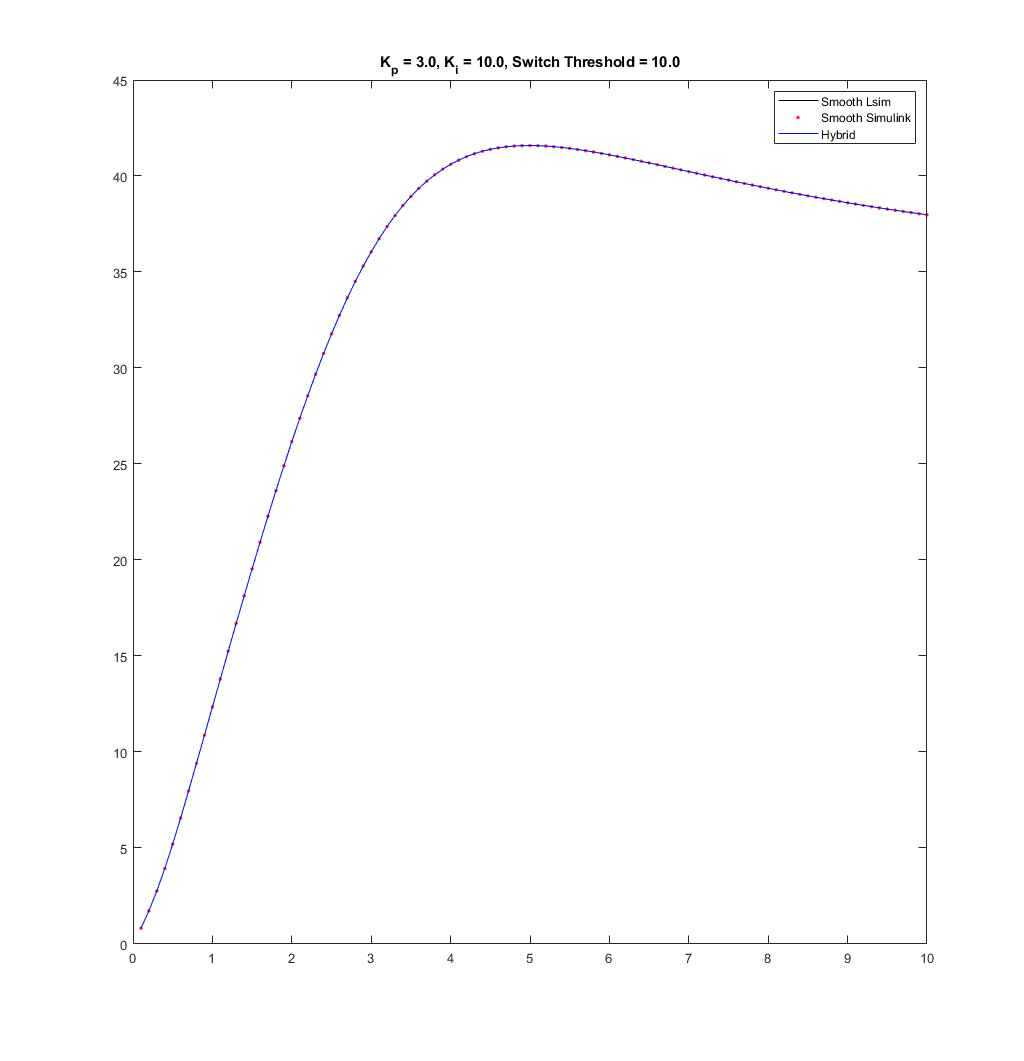

Elapsed time is 7.183626 seconds.


Elapsed time is 7.794444 seconds.


Elapsed time is 7.454593 seconds.


Elapsed time is 7.411417 seconds.


Elapsed time is 7.380782 seconds.


Elapsed time is 7.358005 seconds.


Elapsed time is 7.568601 seconds.


Elapsed time is 7.310348 seconds.


Elapsed time is 7.320430 seconds.


Elapsed time is 7.292831 seconds.


Elapsed time is 7.265298 seconds.


Elapsed time is 7.238649 seconds.


Elapsed time is 7.236897 seconds.


Elapsed time is 7.258263 seconds.


Elapsed time is 7.239365 seconds.


Elapsed time is 7.209577 seconds.


Elapsed time is 7.207693 seconds.


Elapsed time is 7.240197 seconds.


Elapsed time is 7.193631 seconds.


Elapsed time is 7.176833 seconds.


Elapsed time is 7.314593 seconds.


Elapsed time is 7.172538 seconds.


Elapsed time is 7.155484 seconds.


Elapsed time is 7.132789 seconds.


Elapsed time is 7.151935 seconds.


Elapsed time is 7.145819 seconds.


Elapsed time is 7.136706 seconds.


Elapsed time is 7.148227 seconds.


Elapsed time is 7.147334 seconds.


Elapsed time is 7.149612 seconds.


Elapsed time is 7.140634 seconds.


Elapsed time is 7.320932 seconds.


Elapsed time is 7.160356 seconds.


Elapsed time is 7.180027 seconds.


Elapsed time is 7.166335 seconds.


Elapsed time is 7.176566 seconds.


Elapsed time is 7.163158 seconds.


Elapsed time is 7.186766 seconds.


Elapsed time is 7.171493 seconds.


Elapsed time is 7.167058 seconds.


Elapsed time is 7.135448 seconds.


Elapsed time is 7.170237 seconds.


Elapsed time is 7.149420 seconds.


Elapsed time is 7.153844 seconds.


Elapsed time is 7.162380 seconds.


Elapsed time is 7.174950 seconds.


Elapsed time is 7.153870 seconds.


Elapsed time is 7.163397 seconds.


Elapsed time is 7.142547 seconds.


Elapsed time is 7.149773 seconds.


Elapsed time is 7.196060 seconds.


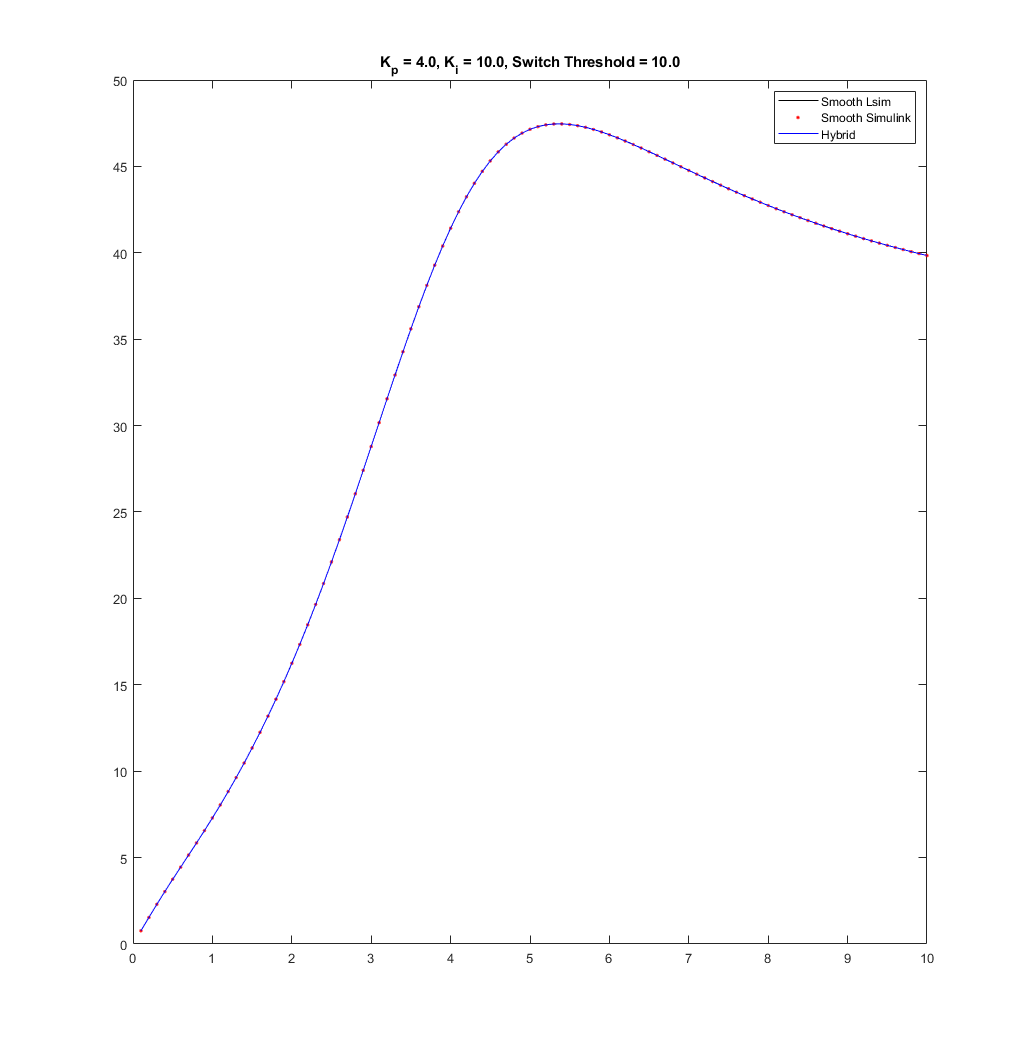

Elapsed time is 7.155514 seconds.


Elapsed time is 7.727054 seconds.


Elapsed time is 7.483380 seconds.


Elapsed time is 7.416461 seconds.


Elapsed time is 7.378448 seconds.


Elapsed time is 8.168821 seconds.


Elapsed time is 7.367076 seconds.


Elapsed time is 7.327952 seconds.


Elapsed time is 7.321055 seconds.


Elapsed time is 7.292234 seconds.


Elapsed time is 7.256973 seconds.


Elapsed time is 7.246604 seconds.


Elapsed time is 7.348334 seconds.


Elapsed time is 7.271130 seconds.


Elapsed time is 7.223667 seconds.


Elapsed time is 7.234132 seconds.


Elapsed time is 7.218624 seconds.


Elapsed time is 7.205368 seconds.


Elapsed time is 7.197925 seconds.


Elapsed time is 7.212145 seconds.


Elapsed time is 7.245325 seconds.


Elapsed time is 7.183939 seconds.


Elapsed time is 7.164099 seconds.


Elapsed time is 7.175893 seconds.


Elapsed time is 7.155963 seconds.


Elapsed time is 7.158359 seconds.


Elapsed time is 7.192281 seconds.


Elapsed time is 7.174255 seconds.


Elapsed time is 7.161014 seconds.


Elapsed time is 7.253318 seconds.


Elapsed time is 7.670931 seconds.


Elapsed time is 7.220415 seconds.


Elapsed time is 7.184632 seconds.


Elapsed time is 7.160189 seconds.


Elapsed time is 7.148350 seconds.


Elapsed time is 7.146088 seconds.


Elapsed time is 7.159037 seconds.


Elapsed time is 7.153226 seconds.


Elapsed time is 7.165957 seconds.


Elapsed time is 7.171093 seconds.


Elapsed time is 7.145187 seconds.


Elapsed time is 7.183260 seconds.


Elapsed time is 7.159559 seconds.


Elapsed time is 7.157754 seconds.


Elapsed time is 7.189384 seconds.


Elapsed time is 7.183153 seconds.


Elapsed time is 7.169010 seconds.


Elapsed time is 7.160233 seconds.


Elapsed time is 7.153844 seconds.


Elapsed time is 7.158913 seconds.


Elapsed time is 7.152370 seconds.


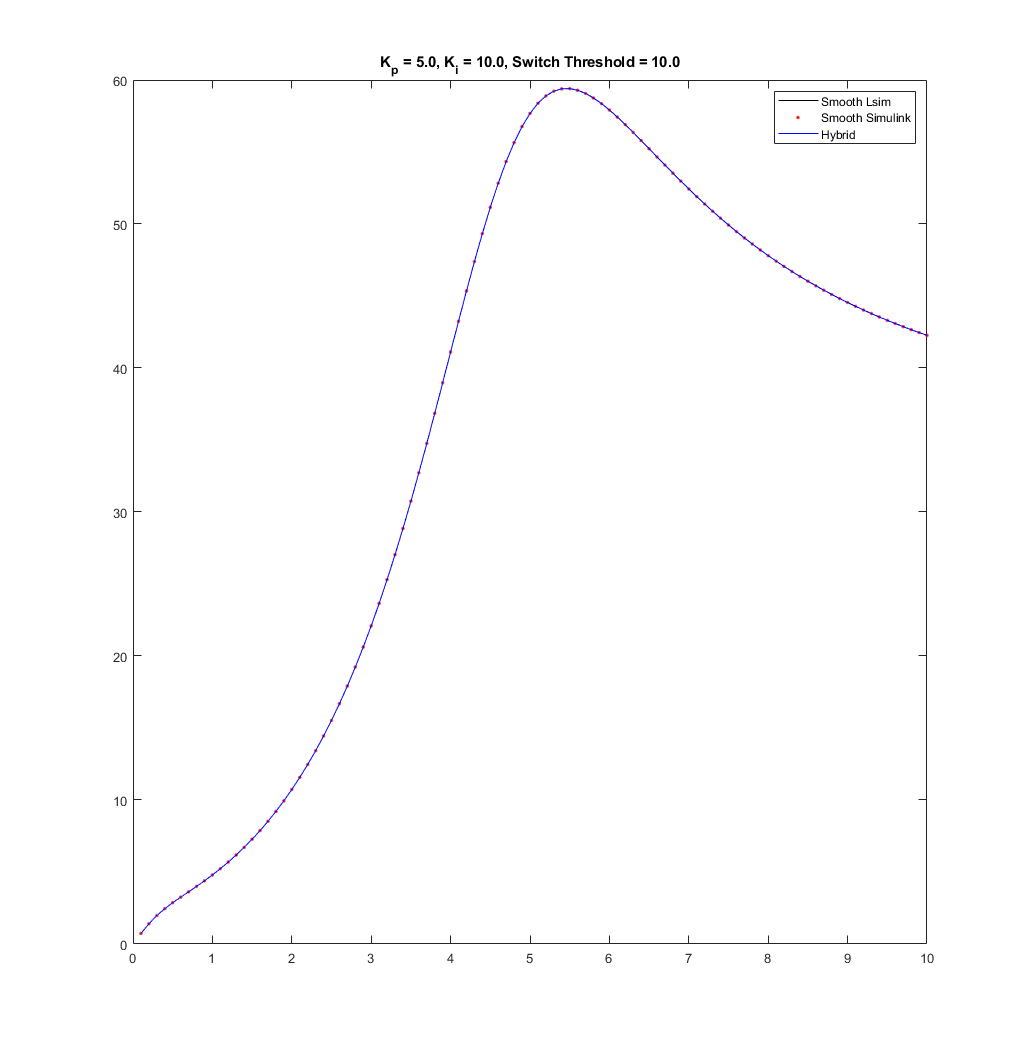

Elapsed time is 7.161284 seconds.


Elapsed time is 7.725127 seconds.


Elapsed time is 7.463030 seconds.


Elapsed time is 7.409800 seconds.


Elapsed time is 7.658878 seconds.


Elapsed time is 7.357629 seconds.


Elapsed time is 7.364938 seconds.


Elapsed time is 7.329072 seconds.


Elapsed time is 7.305363 seconds.


Elapsed time is 7.284781 seconds.


Elapsed time is 7.268762 seconds.


Elapsed time is 7.243742 seconds.


Elapsed time is 7.261426 seconds.


Elapsed time is 7.275588 seconds.


Elapsed time is 7.232347 seconds.


Elapsed time is 7.234252 seconds.


Elapsed time is 7.254143 seconds.


Elapsed time is 7.219164 seconds.


Elapsed time is 7.201900 seconds.


Elapsed time is 7.206697 seconds.


Elapsed time is 7.196778 seconds.


Elapsed time is 7.206014 seconds.


Elapsed time is 7.168953 seconds.


Elapsed time is 7.208819 seconds.


Elapsed time is 7.171064 seconds.


Elapsed time is 7.166319 seconds.


Elapsed time is 7.202844 seconds.


Elapsed time is 7.177216 seconds.


Elapsed time is 7.148706 seconds.


Elapsed time is 7.282142 seconds.


Elapsed time is 7.165647 seconds.


Elapsed time is 7.150913 seconds.


Elapsed time is 7.161009 seconds.


Elapsed time is 7.166675 seconds.


Elapsed time is 7.167892 seconds.


Elapsed time is 7.167343 seconds.


Elapsed time is 7.166041 seconds.


Elapsed time is 7.156478 seconds.


Elapsed time is 7.169998 seconds.


Elapsed time is 7.138604 seconds.


Elapsed time is 7.159237 seconds.


Elapsed time is 7.148184 seconds.


Elapsed time is 7.137421 seconds.


Elapsed time is 7.166927 seconds.


Elapsed time is 7.150532 seconds.


Elapsed time is 7.162536 seconds.


Elapsed time is 7.147804 seconds.


Elapsed time is 7.139036 seconds.


Elapsed time is 7.162489 seconds.


Elapsed time is 7.186433 seconds.


Elapsed time is 7.148440 seconds.


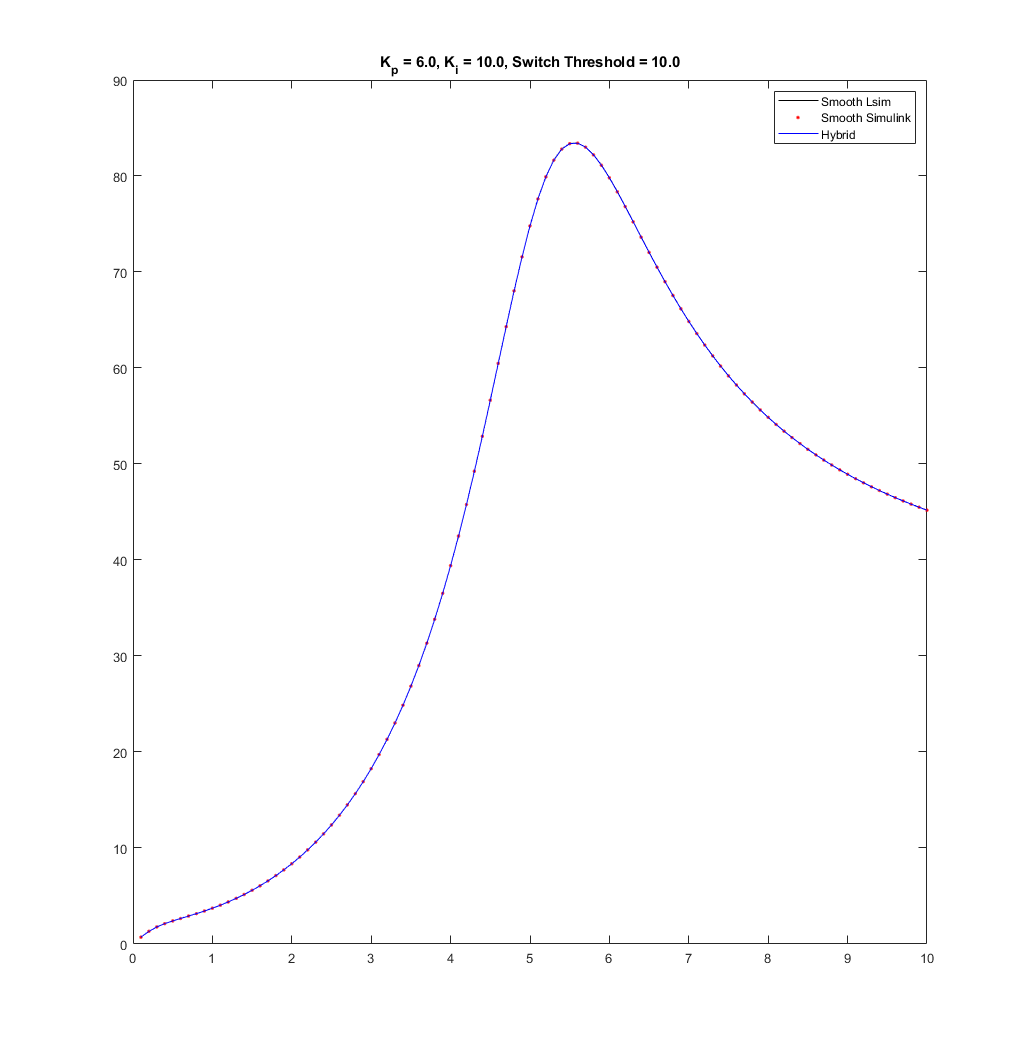

Elapsed time is 7.163763 seconds.


Elapsed time is 7.732568 seconds.


Elapsed time is 7.532174 seconds.


Elapsed time is 7.634659 seconds.


Elapsed time is 7.413081 seconds.


Elapsed time is 7.380567 seconds.


Elapsed time is 7.343094 seconds.


Elapsed time is 7.313401 seconds.


Elapsed time is 7.305171 seconds.


Elapsed time is 7.295706 seconds.


Elapsed time is 7.263451 seconds.


Elapsed time is 7.255855 seconds.


Elapsed time is 7.248768 seconds.


Elapsed time is 7.257197 seconds.


Elapsed time is 7.224123 seconds.


Elapsed time is 7.241246 seconds.


Elapsed time is 7.243250 seconds.


Elapsed time is 7.247780 seconds.


Elapsed time is 7.251730 seconds.


Elapsed time is 7.233580 seconds.


Elapsed time is 7.218763 seconds.


Elapsed time is 7.200132 seconds.


Elapsed time is 7.210745 seconds.


Elapsed time is 7.201458 seconds.


Elapsed time is 7.190085 seconds.


Elapsed time is 7.190586 seconds.


Elapsed time is 7.187571 seconds.


Elapsed time is 7.176564 seconds.


Elapsed time is 7.330216 seconds.


Elapsed time is 7.159613 seconds.


Elapsed time is 7.157385 seconds.


Elapsed time is 7.182502 seconds.


Elapsed time is 7.155528 seconds.


Elapsed time is 7.169273 seconds.


Elapsed time is 7.156062 seconds.


Elapsed time is 7.170742 seconds.


Elapsed time is 7.181821 seconds.


Elapsed time is 7.206217 seconds.


Elapsed time is 7.165958 seconds.


Elapsed time is 7.161416 seconds.


Elapsed time is 7.168401 seconds.


Elapsed time is 7.168255 seconds.


Elapsed time is 7.189705 seconds.


Elapsed time is 7.198682 seconds.


Elapsed time is 7.167207 seconds.


Elapsed time is 7.170870 seconds.


Elapsed time is 7.153886 seconds.


Elapsed time is 7.196178 seconds.


Elapsed time is 7.161423 seconds.


Elapsed time is 7.185980 seconds.


Elapsed time is 7.171265 seconds.


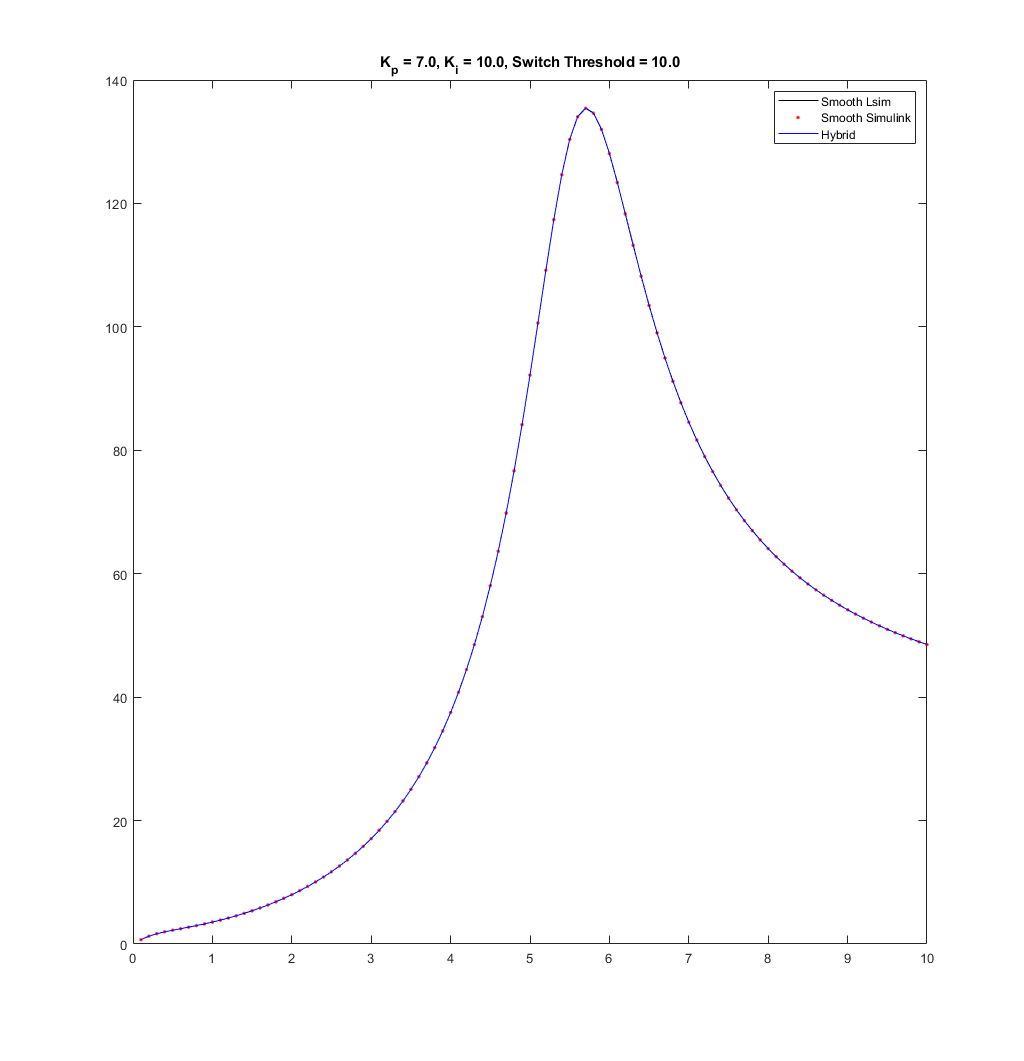

Elapsed time is 7.150922 seconds.


Elapsed time is 7.726888 seconds.


Elapsed time is 7.652291 seconds.


Elapsed time is 7.431528 seconds.


Elapsed time is 7.402212 seconds.


Elapsed time is 7.341104 seconds.


Elapsed time is 7.356601 seconds.


Elapsed time is 7.327611 seconds.


Elapsed time is 7.324259 seconds.


Elapsed time is 7.304940 seconds.


Elapsed time is 7.291127 seconds.


Elapsed time is 7.267138 seconds.


Elapsed time is 7.262744 seconds.


Elapsed time is 7.253598 seconds.


Elapsed time is 7.243692 seconds.


Elapsed time is 7.231078 seconds.


Elapsed time is 7.271263 seconds.


Elapsed time is 7.222719 seconds.


Elapsed time is 7.233619 seconds.


Elapsed time is 7.214132 seconds.


Elapsed time is 7.205560 seconds.


Elapsed time is 7.207457 seconds.


Elapsed time is 7.194440 seconds.


Elapsed time is 7.214549 seconds.


Elapsed time is 7.200376 seconds.


Elapsed time is 7.204587 seconds.


Elapsed time is 7.187800 seconds.


Elapsed time is 7.356751 seconds.


Elapsed time is 7.201875 seconds.


Elapsed time is 7.208500 seconds.


Elapsed time is 7.194456 seconds.


Elapsed time is 7.185083 seconds.


Elapsed time is 7.222877 seconds.


Elapsed time is 7.186653 seconds.


Elapsed time is 7.177379 seconds.


Elapsed time is 7.184130 seconds.


Elapsed time is 7.185944 seconds.


Elapsed time is 7.165055 seconds.


Elapsed time is 7.177409 seconds.


Elapsed time is 7.180013 seconds.


Elapsed time is 7.168204 seconds.


Elapsed time is 7.212093 seconds.


Elapsed time is 7.186187 seconds.


Elapsed time is 7.187545 seconds.


Elapsed time is 7.180809 seconds.


Elapsed time is 7.167236 seconds.


Elapsed time is 7.245172 seconds.


Elapsed time is 7.162798 seconds.


Elapsed time is 7.184159 seconds.


Elapsed time is 7.194206 seconds.


Elapsed time is 7.172495 seconds.


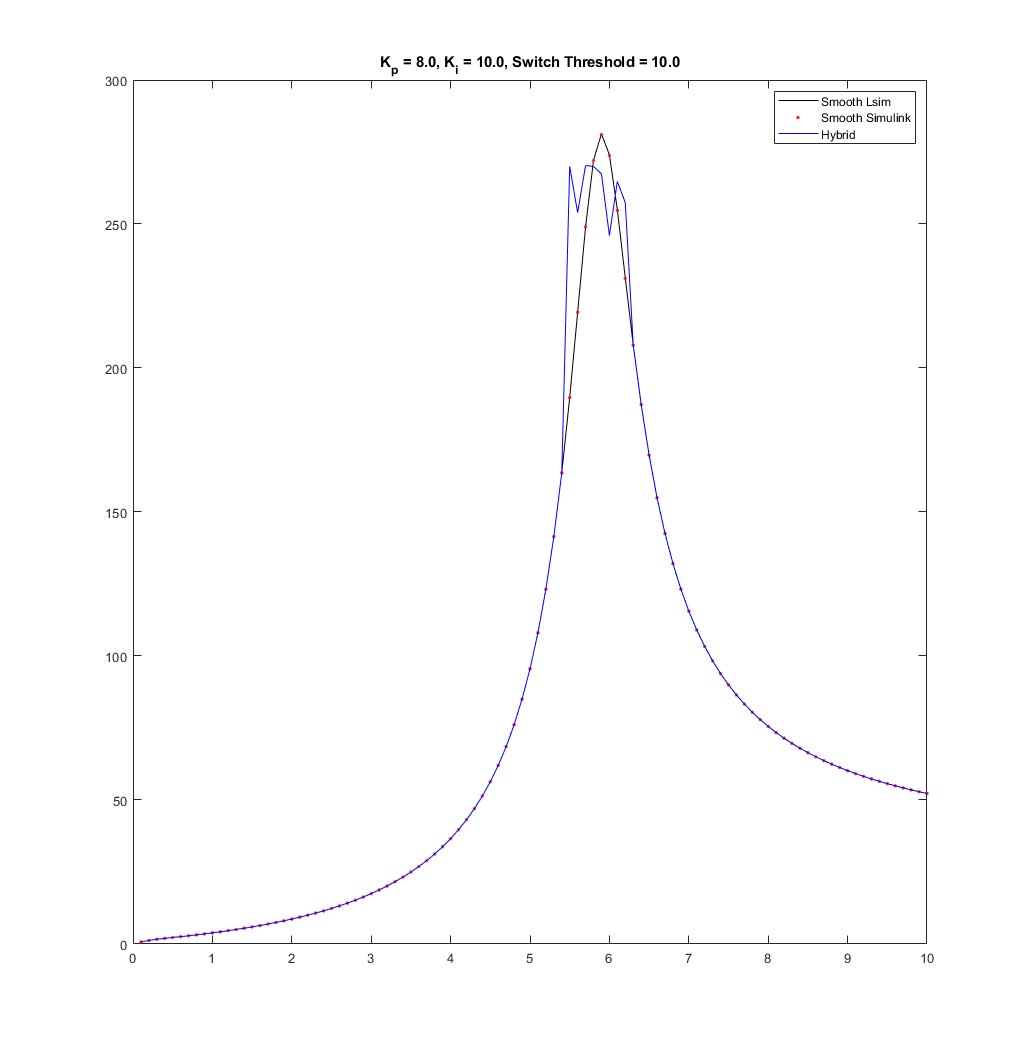

Elapsed time is 7.173555 seconds.


Elapsed time is 7.879109 seconds.


Elapsed time is 7.466088 seconds.


Elapsed time is 7.416439 seconds.


Elapsed time is 7.372458 seconds.


Elapsed time is 7.364847 seconds.


Elapsed time is 7.335889 seconds.


Elapsed time is 7.316947 seconds.


Elapsed time is 7.313936 seconds.


Elapsed time is 7.263802 seconds.


Elapsed time is 7.271526 seconds.


Elapsed time is 7.282661 seconds.


Elapsed time is 7.268888 seconds.


Elapsed time is 7.266748 seconds.


Elapsed time is 7.258890 seconds.


Elapsed time is 7.266908 seconds.


Elapsed time is 7.252504 seconds.


Elapsed time is 7.248092 seconds.


Elapsed time is 7.254604 seconds.


Elapsed time is 7.234477 seconds.


Elapsed time is 7.231554 seconds.


Elapsed time is 7.261650 seconds.


Elapsed time is 7.223311 seconds.


Elapsed time is 7.225018 seconds.


Elapsed time is 7.211187 seconds.


Elapsed time is 7.238816 seconds.


Elapsed time is 7.353121 seconds.


Elapsed time is 7.207560 seconds.


Elapsed time is 7.221153 seconds.


Elapsed time is 7.214972 seconds.


Elapsed time is 7.205949 seconds.


Elapsed time is 7.238852 seconds.


Elapsed time is 7.245508 seconds.


Elapsed time is 7.215201 seconds.


Elapsed time is 7.199439 seconds.


Elapsed time is 7.211457 seconds.


Elapsed time is 7.210809 seconds.


Elapsed time is 7.232301 seconds.


Elapsed time is 7.223554 seconds.


Elapsed time is 7.222326 seconds.


Elapsed time is 7.304269 seconds.


Elapsed time is 7.213817 seconds.


Elapsed time is 7.196208 seconds.


Elapsed time is 7.197022 seconds.


Elapsed time is 7.197592 seconds.


Elapsed time is 7.214041 seconds.


Elapsed time is 7.186487 seconds.


Elapsed time is 7.194359 seconds.


Elapsed time is 7.185882 seconds.


Elapsed time is 7.182878 seconds.


Elapsed time is 7.184584 seconds.


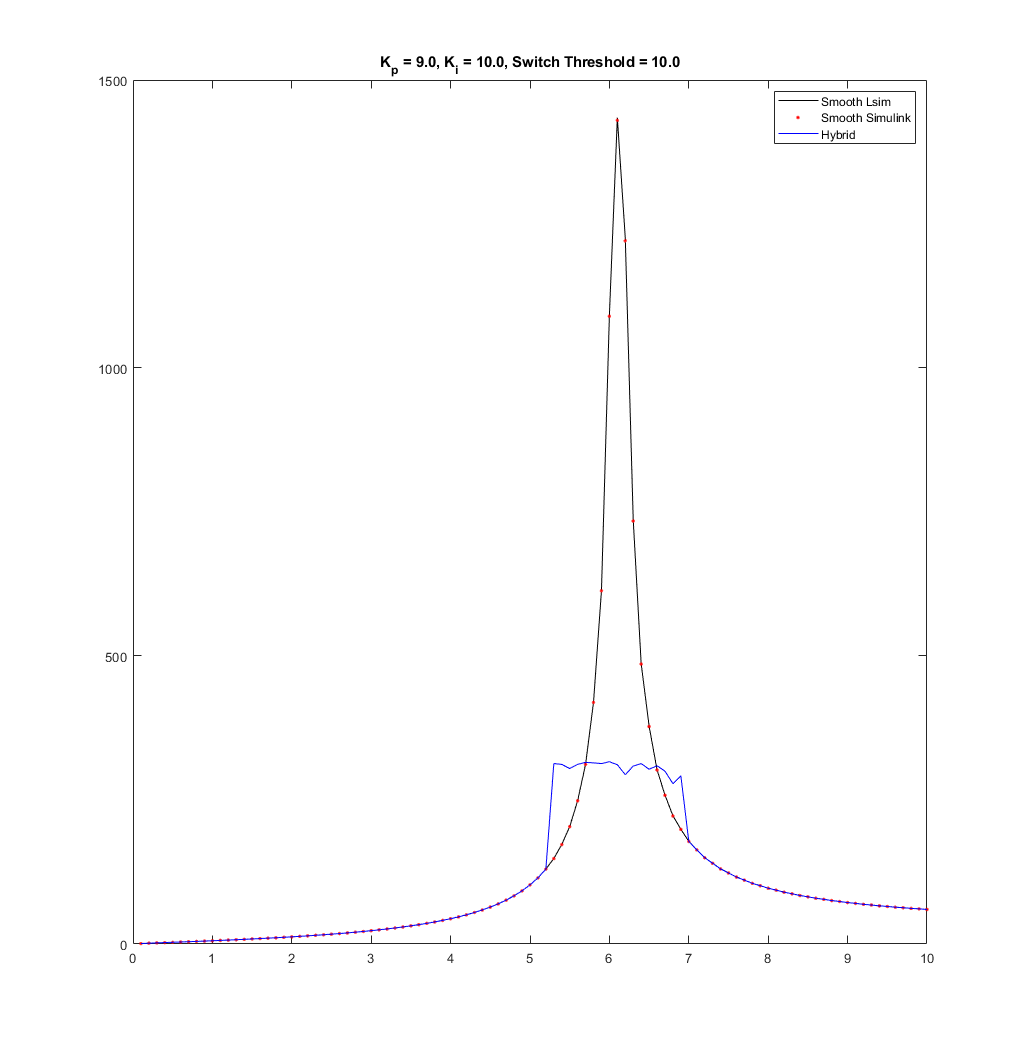

Elapsed time is 7.520109 seconds.


Elapsed time is 7.748327 seconds.


Elapsed time is 7.474832 seconds.


Elapsed time is 7.416728 seconds.


Elapsed time is 7.413546 seconds.


Elapsed time is 7.365467 seconds.


Elapsed time is 7.349918 seconds.


Elapsed time is 7.325189 seconds.


Elapsed time is 7.335195 seconds.


Elapsed time is 7.332100 seconds.


Elapsed time is 7.323913 seconds.


Elapsed time is 7.310695 seconds.


Elapsed time is 7.312358 seconds.


Elapsed time is 7.317727 seconds.


Elapsed time is 7.350099 seconds.


Elapsed time is 7.317015 seconds.


Elapsed time is 7.326064 seconds.


Elapsed time is 7.336044 seconds.


Elapsed time is 7.300071 seconds.


Elapsed time is 7.312994 seconds.


Elapsed time is 7.315350 seconds.


Elapsed time is 7.326149 seconds.


Elapsed time is 7.349571 seconds.


Elapsed time is 7.330752 seconds.


Elapsed time is 7.332115 seconds.


Elapsed time is 7.672137 seconds.


Elapsed time is 7.344944 seconds.


Elapsed time is 7.337333 seconds.


Elapsed time is 7.355887 seconds.


Elapsed time is 7.328236 seconds.


Elapsed time is 7.351649 seconds.


Elapsed time is 7.342727 seconds.


Elapsed time is 7.332391 seconds.


Elapsed time is 7.358089 seconds.


Elapsed time is 7.352081 seconds.


Elapsed time is 7.351096 seconds.


Elapsed time is 7.350501 seconds.


Elapsed time is 7.339890 seconds.


Elapsed time is 7.345683 seconds.


Elapsed time is 7.372389 seconds.


Elapsed time is 7.334985 seconds.


Elapsed time is 7.343920 seconds.


Elapsed time is 7.357113 seconds.


Elapsed time is 7.349191 seconds.


Elapsed time is 7.355054 seconds.


Elapsed time is 7.336925 seconds.


Elapsed time is 7.356322 seconds.


Elapsed time is 7.339647 seconds.


Elapsed time is 7.381925 seconds.


Elapsed time is 7.348124 seconds.


Elapsed time is 7.545768 seconds.


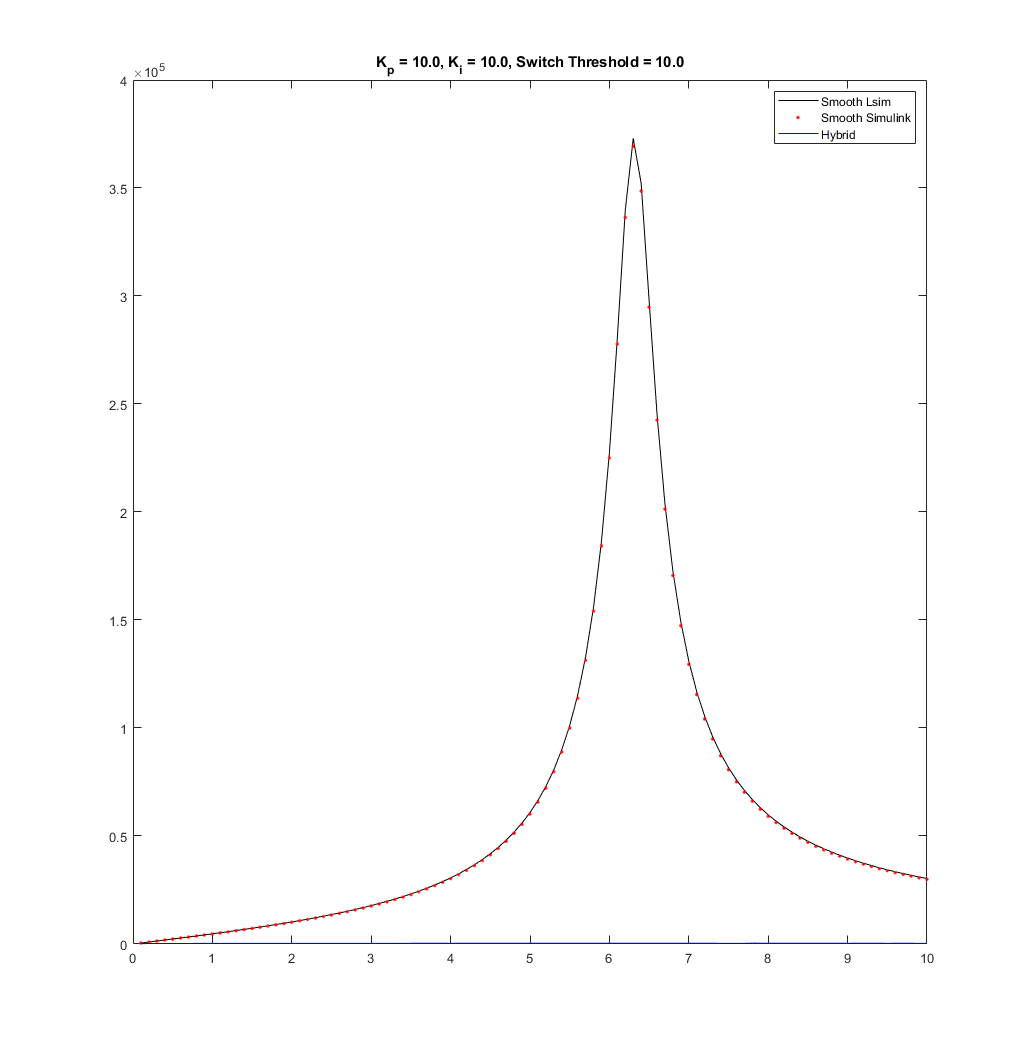

Elapsed time is 7.341514 seconds.


Elapsed time is 7.759674 seconds.


Elapsed time is 7.473787 seconds.


Elapsed time is 7.450769 seconds.


Elapsed time is 7.405178 seconds.


Elapsed time is 7.370530 seconds.


Elapsed time is 7.352392 seconds.


Elapsed time is 7.348027 seconds.


Elapsed time is 7.335664 seconds.


Elapsed time is 7.295429 seconds.


Elapsed time is 7.288260 seconds.


Elapsed time is 7.281185 seconds.


Elapsed time is 7.257450 seconds.


Elapsed time is 7.281455 seconds.


Elapsed time is 7.220907 seconds.


Elapsed time is 7.216579 seconds.


Elapsed time is 7.220508 seconds.


Elapsed time is 7.207646 seconds.


Elapsed time is 7.208775 seconds.


Elapsed time is 7.191304 seconds.


Elapsed time is 7.195535 seconds.


Elapsed time is 7.199211 seconds.


Elapsed time is 7.186959 seconds.


Elapsed time is 7.183660 seconds.


Elapsed time is 7.438240 seconds.


Elapsed time is 7.176155 seconds.


Elapsed time is 7.167267 seconds.


Elapsed time is 7.174698 seconds.


Elapsed time is 7.172438 seconds.


Elapsed time is 7.157569 seconds.


Elapsed time is 7.165189 seconds.


Elapsed time is 7.169006 seconds.


Elapsed time is 7.164034 seconds.


Elapsed time is 7.180859 seconds.


Elapsed time is 7.162419 seconds.


Elapsed time is 7.175174 seconds.


Elapsed time is 7.185833 seconds.


Elapsed time is 7.150449 seconds.


Elapsed time is 7.194134 seconds.


Elapsed time is 7.157354 seconds.


Elapsed time is 7.169099 seconds.


Elapsed time is 7.196326 seconds.


Elapsed time is 7.158568 seconds.


Elapsed time is 7.167365 seconds.


Elapsed time is 7.221000 seconds.


Elapsed time is 7.188391 seconds.


Elapsed time is 7.175410 seconds.


Elapsed time is 7.167256 seconds.


Elapsed time is 7.165868 seconds.


Elapsed time is 7.315313 seconds.


Elapsed time is 7.188780 seconds.


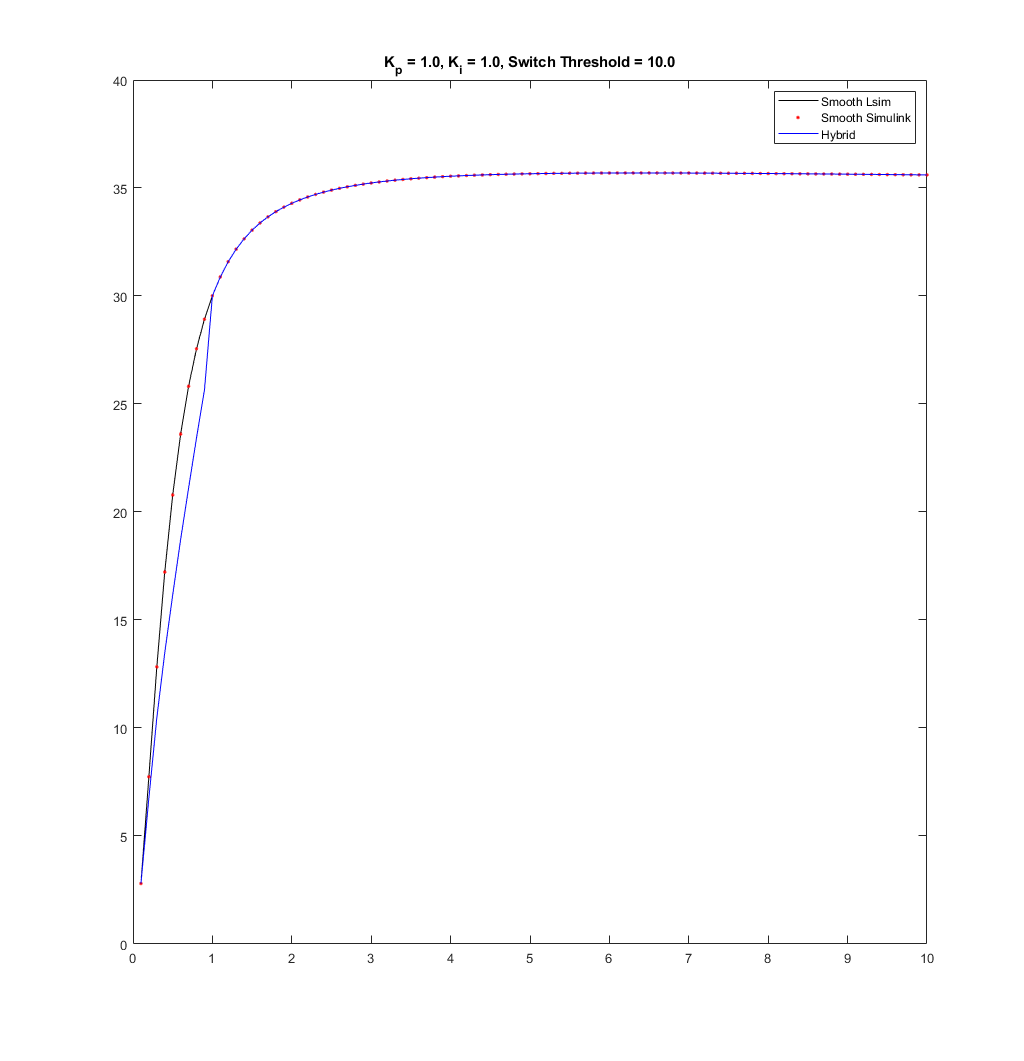

Elapsed time is 7.171462 seconds.


Elapsed time is 7.735315 seconds.


Elapsed time is 7.493596 seconds.


Elapsed time is 7.441540 seconds.


Elapsed time is 7.413725 seconds.


Elapsed time is 7.397493 seconds.


Elapsed time is 7.377991 seconds.


Elapsed time is 7.353494 seconds.


Elapsed time is 7.333788 seconds.


Elapsed time is 7.321568 seconds.


Elapsed time is 7.327237 seconds.


Elapsed time is 7.266698 seconds.


Elapsed time is 7.227523 seconds.


Elapsed time is 7.222300 seconds.


Elapsed time is 7.219433 seconds.


Elapsed time is 7.226369 seconds.


Elapsed time is 7.209611 seconds.


Elapsed time is 7.208591 seconds.


Elapsed time is 7.216253 seconds.


Elapsed time is 7.205766 seconds.


Elapsed time is 7.195951 seconds.


Elapsed time is 7.202191 seconds.


Elapsed time is 7.197437 seconds.


Elapsed time is 7.394606 seconds.


Elapsed time is 7.180148 seconds.


Elapsed time is 7.191743 seconds.


Elapsed time is 7.183166 seconds.


Elapsed time is 7.168543 seconds.


Elapsed time is 7.197557 seconds.


Elapsed time is 7.178429 seconds.


Elapsed time is 7.201060 seconds.


Elapsed time is 7.164391 seconds.


Elapsed time is 7.156496 seconds.


Elapsed time is 7.212389 seconds.


Elapsed time is 7.188850 seconds.


Elapsed time is 7.169901 seconds.


Elapsed time is 7.167684 seconds.


Elapsed time is 7.192039 seconds.


Elapsed time is 7.166442 seconds.


Elapsed time is 7.192580 seconds.


Elapsed time is 7.164197 seconds.


Elapsed time is 7.186819 seconds.


Elapsed time is 7.207154 seconds.


Elapsed time is 7.171722 seconds.


Elapsed time is 7.166618 seconds.


Elapsed time is 7.164750 seconds.


Elapsed time is 7.155622 seconds.


Elapsed time is 7.158986 seconds.


Elapsed time is 7.337464 seconds.


Elapsed time is 7.164182 seconds.


Elapsed time is 7.170319 seconds.


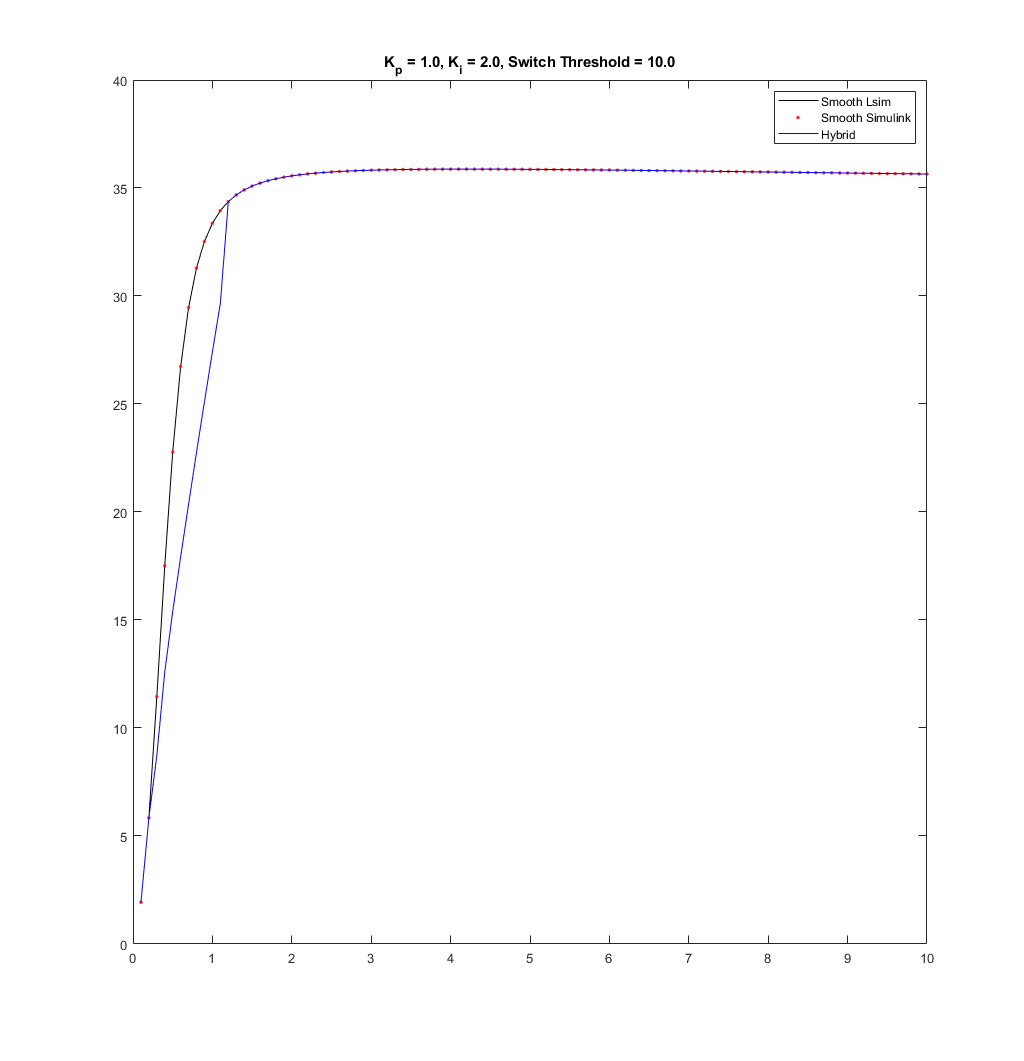

Elapsed time is 7.170095 seconds.


Elapsed time is 7.736794 seconds.


Elapsed time is 7.475619 seconds.


Elapsed time is 7.434437 seconds.


Elapsed time is 7.392693 seconds.


Elapsed time is 7.370239 seconds.


Elapsed time is 7.358040 seconds.


Elapsed time is 7.340237 seconds.


Elapsed time is 7.312086 seconds.


Elapsed time is 7.326646 seconds.


Elapsed time is 7.286424 seconds.


Elapsed time is 7.279157 seconds.


Elapsed time is 7.258311 seconds.


Elapsed time is 7.215869 seconds.


Elapsed time is 7.209382 seconds.


Elapsed time is 7.221268 seconds.


Elapsed time is 7.239702 seconds.


Elapsed time is 7.201089 seconds.


Elapsed time is 7.197560 seconds.


Elapsed time is 7.202055 seconds.


Elapsed time is 7.184726 seconds.


Elapsed time is 7.178502 seconds.


Elapsed time is 7.366639 seconds.


Elapsed time is 7.190836 seconds.


Elapsed time is 7.153594 seconds.


Elapsed time is 7.175257 seconds.


Elapsed time is 7.163246 seconds.


Elapsed time is 7.162135 seconds.


Elapsed time is 7.161988 seconds.


Elapsed time is 7.200680 seconds.


Elapsed time is 7.162026 seconds.


Elapsed time is 7.166564 seconds.


Elapsed time is 7.160470 seconds.


Elapsed time is 7.154752 seconds.


Elapsed time is 7.213991 seconds.


Elapsed time is 7.160584 seconds.


Elapsed time is 7.200011 seconds.


Elapsed time is 7.162241 seconds.


Elapsed time is 7.161026 seconds.


Elapsed time is 7.178433 seconds.


Elapsed time is 7.164621 seconds.


Elapsed time is 7.154536 seconds.


Elapsed time is 7.166578 seconds.


Elapsed time is 7.172447 seconds.


Elapsed time is 7.158638 seconds.


Elapsed time is 7.162367 seconds.


Elapsed time is 7.155266 seconds.


Elapsed time is 7.297440 seconds.


Elapsed time is 7.172933 seconds.


Elapsed time is 7.192914 seconds.


Elapsed time is 7.162976 seconds.


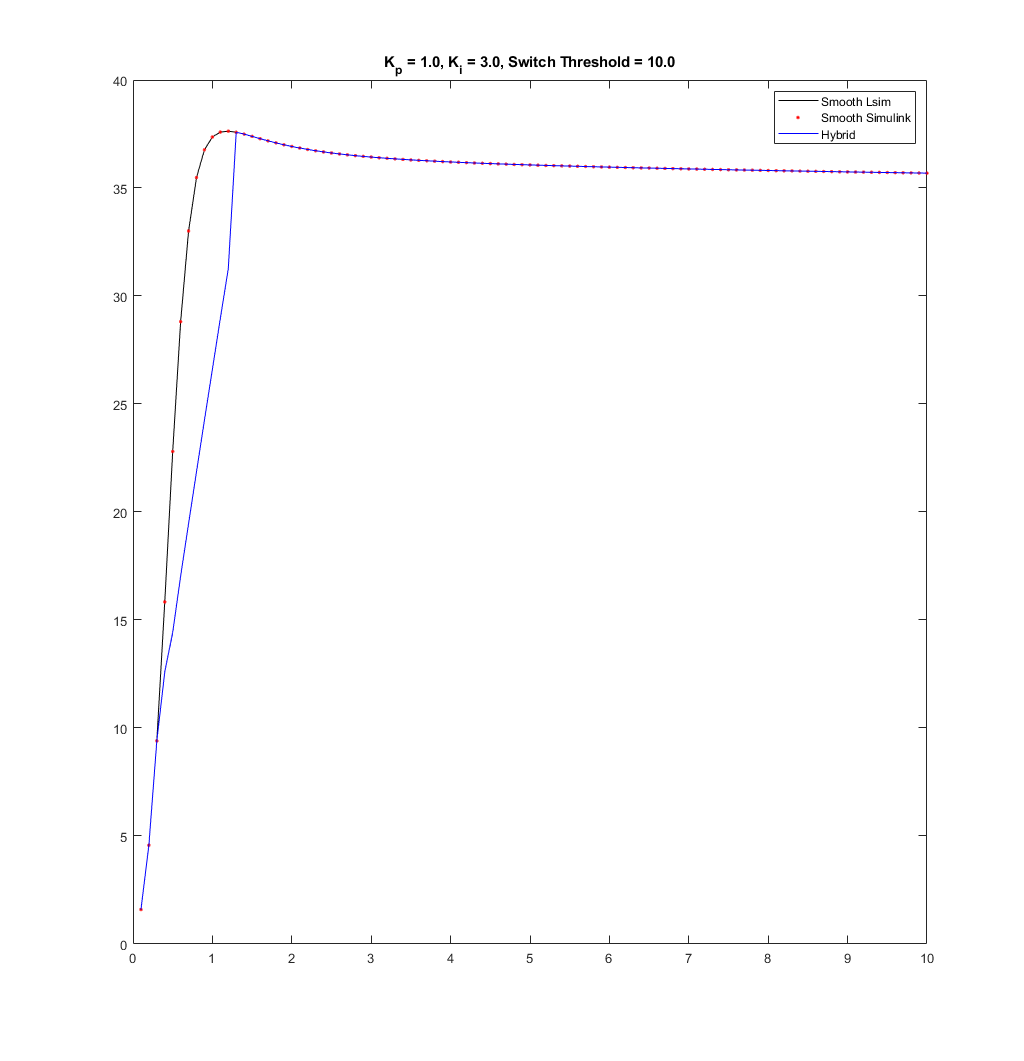

Elapsed time is 7.169420 seconds.


Elapsed time is 7.723271 seconds.


Elapsed time is 7.482691 seconds.


Elapsed time is 7.420310 seconds.


Elapsed time is 7.398500 seconds.


Elapsed time is 7.411016 seconds.


Elapsed time is 7.354060 seconds.


Elapsed time is 7.324398 seconds.


Elapsed time is 7.369594 seconds.


Elapsed time is 7.316997 seconds.


Elapsed time is 7.287233 seconds.


Elapsed time is 7.253496 seconds.


Elapsed time is 7.274268 seconds.


Elapsed time is 7.266271 seconds.


Elapsed time is 7.220376 seconds.


Elapsed time is 7.230368 seconds.


Elapsed time is 7.204607 seconds.


Elapsed time is 7.223254 seconds.


Elapsed time is 7.208410 seconds.


Elapsed time is 7.216206 seconds.


Elapsed time is 7.190071 seconds.


Elapsed time is 7.330817 seconds.


Elapsed time is 7.212366 seconds.


Elapsed time is 7.178046 seconds.


Elapsed time is 7.181472 seconds.


Elapsed time is 7.179318 seconds.


Elapsed time is 7.185608 seconds.


Elapsed time is 7.157247 seconds.


Elapsed time is 7.215182 seconds.


Elapsed time is 7.189090 seconds.


Elapsed time is 7.176714 seconds.


Elapsed time is 7.202763 seconds.


Elapsed time is 7.162259 seconds.


Elapsed time is 7.169551 seconds.


Elapsed time is 7.184467 seconds.


Elapsed time is 7.196039 seconds.


Elapsed time is 7.177075 seconds.


Elapsed time is 7.177937 seconds.


Elapsed time is 7.169375 seconds.


Elapsed time is 7.245111 seconds.


Elapsed time is 7.213158 seconds.


Elapsed time is 7.160531 seconds.


Elapsed time is 7.174283 seconds.


Elapsed time is 7.156302 seconds.


Elapsed time is 7.208388 seconds.


Elapsed time is 7.206038 seconds.


Elapsed time is 7.326663 seconds.


Elapsed time is 7.171247 seconds.


Elapsed time is 7.137829 seconds.


Elapsed time is 7.150607 seconds.


Elapsed time is 7.176575 seconds.


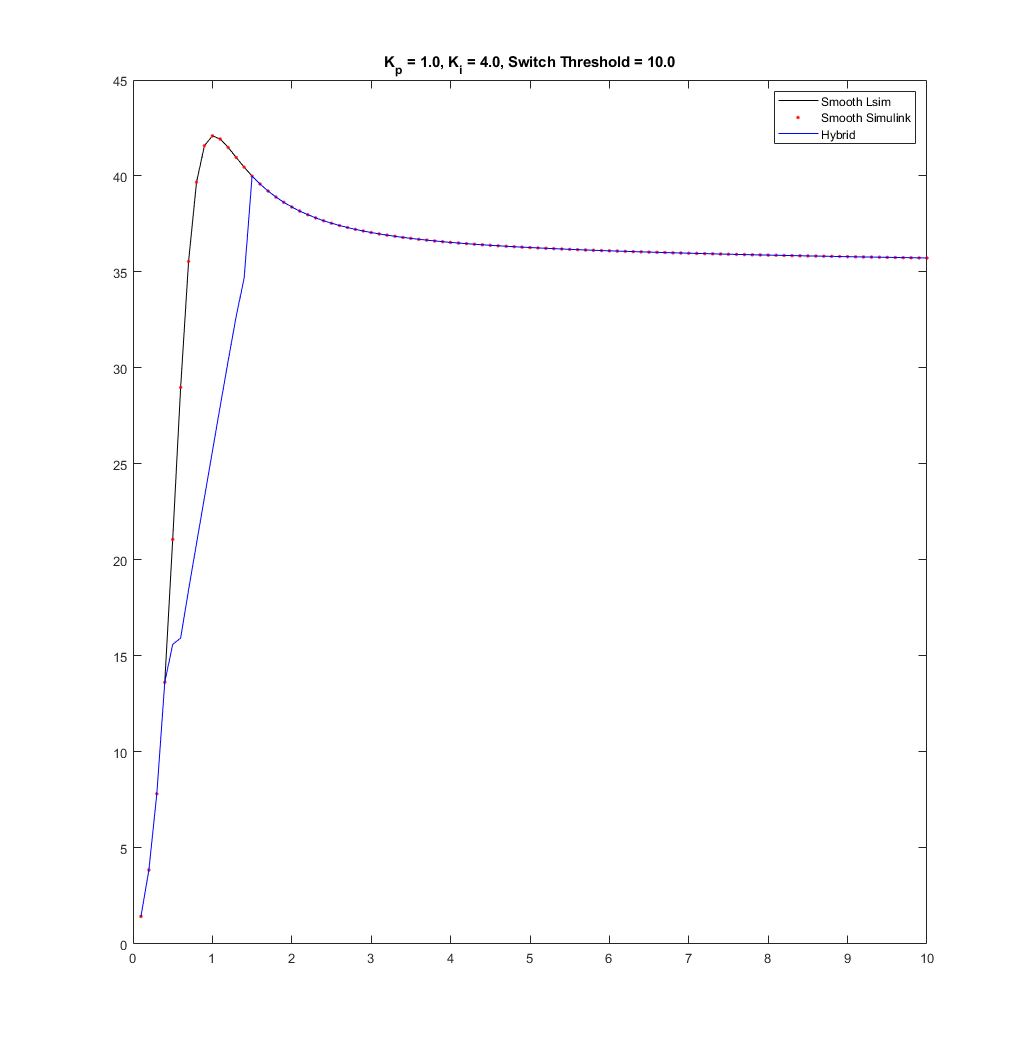

Elapsed time is 7.156838 seconds.


Elapsed time is 7.754930 seconds.


Elapsed time is 7.487762 seconds.


Elapsed time is 7.443125 seconds.


Elapsed time is 7.394560 seconds.


Elapsed time is 7.395228 seconds.


Elapsed time is 7.371230 seconds.


Elapsed time is 7.357537 seconds.


Elapsed time is 7.324633 seconds.


Elapsed time is 7.310079 seconds.


Elapsed time is 7.298974 seconds.


Elapsed time is 7.266367 seconds.


Elapsed time is 7.245165 seconds.


Elapsed time is 7.271072 seconds.


Elapsed time is 7.221776 seconds.


Elapsed time is 7.203132 seconds.


Elapsed time is 7.216240 seconds.


Elapsed time is 7.200494 seconds.


Elapsed time is 7.189026 seconds.


Elapsed time is 7.181856 seconds.


Elapsed time is 7.335478 seconds.


Elapsed time is 7.191599 seconds.


Elapsed time is 7.183600 seconds.


Elapsed time is 7.190549 seconds.


Elapsed time is 7.174288 seconds.


Elapsed time is 7.168725 seconds.


Elapsed time is 7.178754 seconds.


Elapsed time is 7.168106 seconds.


Elapsed time is 7.194125 seconds.


Elapsed time is 7.181528 seconds.


Elapsed time is 7.169926 seconds.


Elapsed time is 7.179095 seconds.


Elapsed time is 7.174800 seconds.


Elapsed time is 7.174403 seconds.


Elapsed time is 7.214875 seconds.


Elapsed time is 7.182440 seconds.


Elapsed time is 7.165454 seconds.


Elapsed time is 7.200400 seconds.


Elapsed time is 7.171712 seconds.


Elapsed time is 7.194899 seconds.


Elapsed time is 7.161602 seconds.


Elapsed time is 7.159000 seconds.


Elapsed time is 7.171077 seconds.


Elapsed time is 7.209715 seconds.


Elapsed time is 7.200926 seconds.


Elapsed time is 7.333654 seconds.


Elapsed time is 7.212759 seconds.


Elapsed time is 7.186822 seconds.


Elapsed time is 7.192706 seconds.


Elapsed time is 7.190229 seconds.


Elapsed time is 7.160495 seconds.


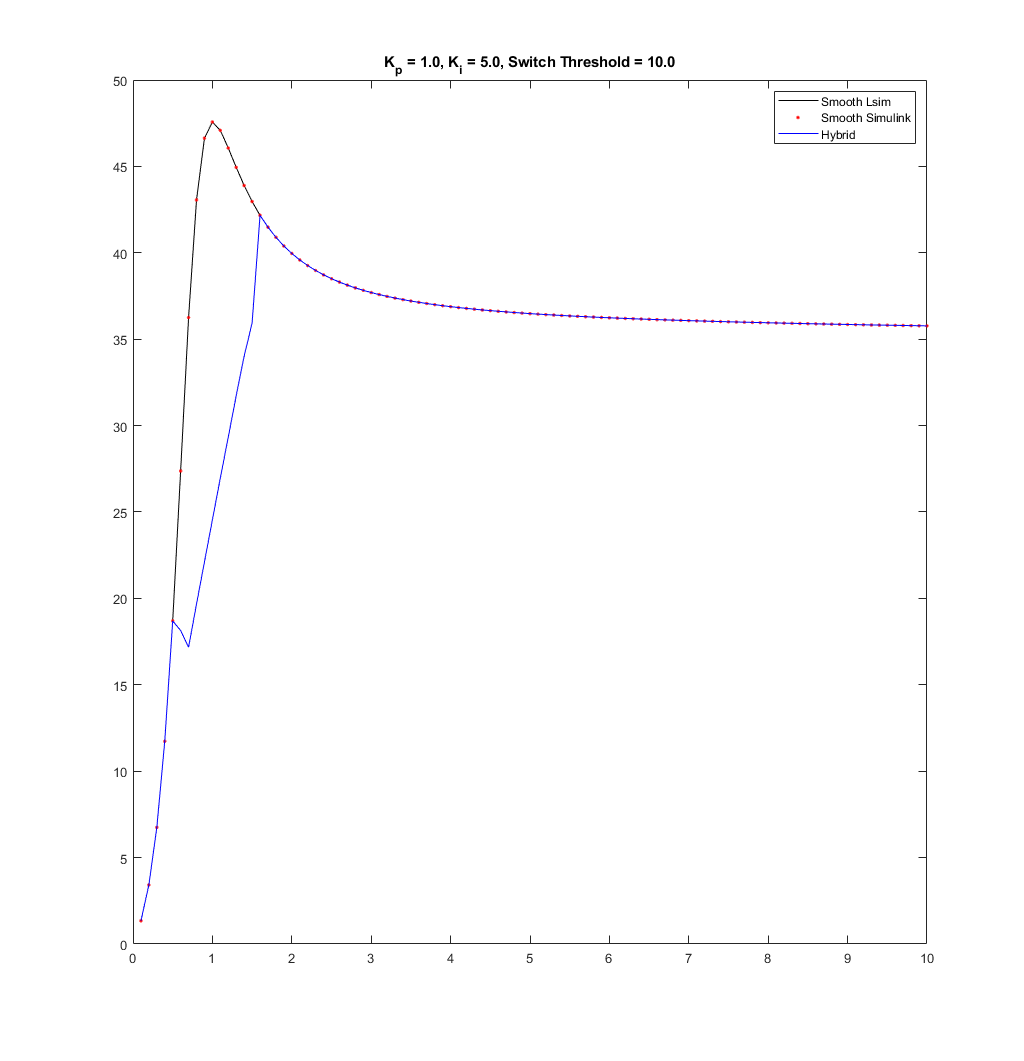

Elapsed time is 7.188709 seconds.


Elapsed time is 7.745034 seconds.


Elapsed time is 7.542552 seconds.


Elapsed time is 7.442526 seconds.


Elapsed time is 7.404530 seconds.


Elapsed time is 7.392357 seconds.


Elapsed time is 7.383784 seconds.


Elapsed time is 7.370561 seconds.


Elapsed time is 7.340596 seconds.


Elapsed time is 7.308821 seconds.


Elapsed time is 7.288178 seconds.


Elapsed time is 7.304250 seconds.


Elapsed time is 7.255735 seconds.


Elapsed time is 7.246834 seconds.


Elapsed time is 7.240879 seconds.


Elapsed time is 7.240179 seconds.


Elapsed time is 7.211696 seconds.


Elapsed time is 7.264690 seconds.


Elapsed time is 7.185821 seconds.


Elapsed time is 7.376888 seconds.


Elapsed time is 7.193335 seconds.


Elapsed time is 7.201162 seconds.


Elapsed time is 7.188434 seconds.


Elapsed time is 7.190394 seconds.


Elapsed time is 7.185311 seconds.


Elapsed time is 7.182070 seconds.


Elapsed time is 7.167165 seconds.


Elapsed time is 7.198223 seconds.


Elapsed time is 7.296788 seconds.


Elapsed time is 7.305812 seconds.


Elapsed time is 7.195307 seconds.


Elapsed time is 7.180241 seconds.


Elapsed time is 7.211955 seconds.


Elapsed time is 7.220909 seconds.


Elapsed time is 7.169202 seconds.


Elapsed time is 7.187603 seconds.


Elapsed time is 7.168395 seconds.


Elapsed time is 7.173626 seconds.


Elapsed time is 7.176775 seconds.


Elapsed time is 7.176382 seconds.


Elapsed time is 7.166289 seconds.


Elapsed time is 7.171791 seconds.


Elapsed time is 7.162890 seconds.


Elapsed time is 7.172284 seconds.


Elapsed time is 7.333919 seconds.


Elapsed time is 7.191027 seconds.


Elapsed time is 7.155265 seconds.


Elapsed time is 7.172625 seconds.


Elapsed time is 7.191516 seconds.


Elapsed time is 7.192470 seconds.


Elapsed time is 7.174327 seconds.


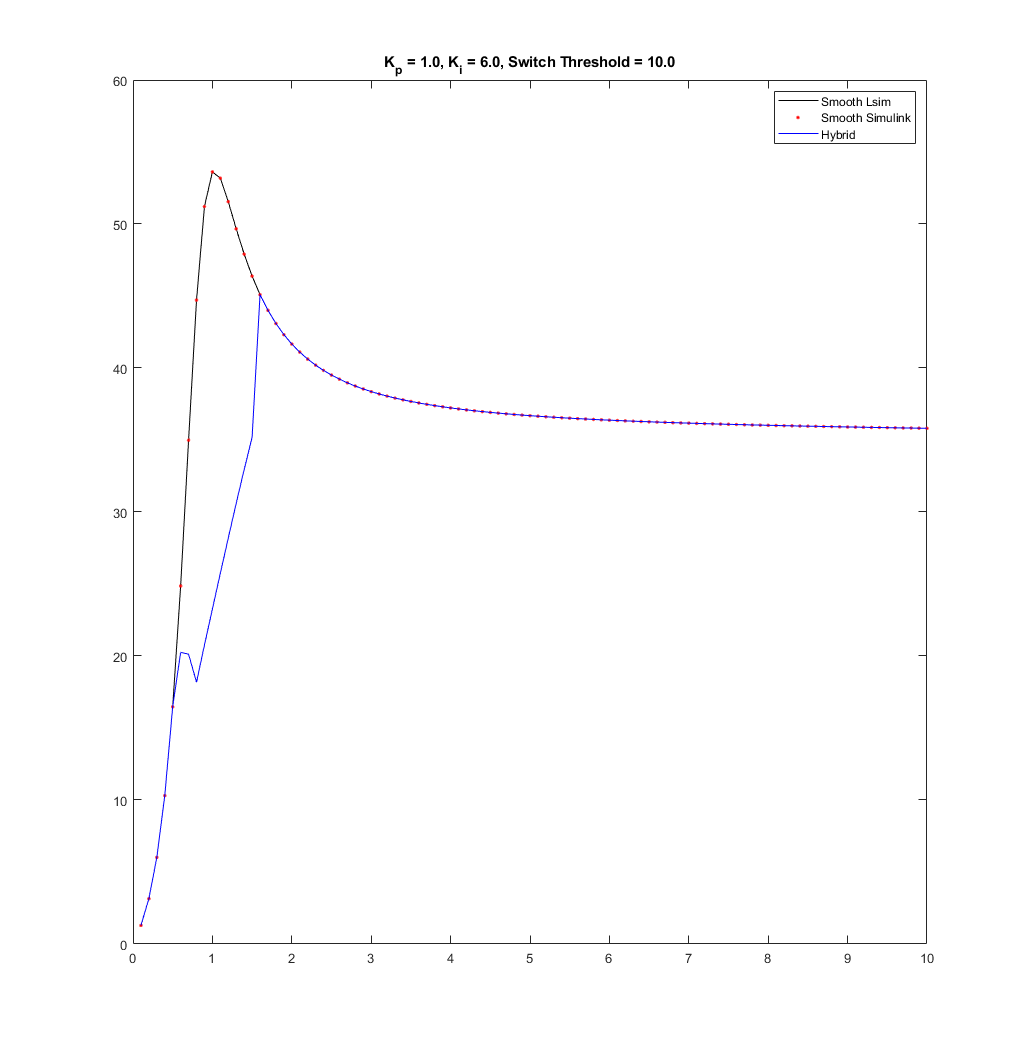

Elapsed time is 7.184904 seconds.


Elapsed time is 7.757946 seconds.


Elapsed time is 7.491521 seconds.


Elapsed time is 7.458006 seconds.


Elapsed time is 7.404945 seconds.


Elapsed time is 7.390127 seconds.


Elapsed time is 7.368330 seconds.


Elapsed time is 7.351212 seconds.


Elapsed time is 7.324782 seconds.


Elapsed time is 7.364900 seconds.


Elapsed time is 7.278689 seconds.


Elapsed time is 7.277219 seconds.


Elapsed time is 7.257638 seconds.


Elapsed time is 7.240876 seconds.


Elapsed time is 7.213397 seconds.


Elapsed time is 7.216445 seconds.


Elapsed time is 7.239478 seconds.


Elapsed time is 7.207226 seconds.


Elapsed time is 7.406615 seconds.


Elapsed time is 7.190776 seconds.


Elapsed time is 7.186256 seconds.


Elapsed time is 7.246826 seconds.


Elapsed time is 7.490688 seconds.


Elapsed time is 7.423185 seconds.


Elapsed time is 7.456175 seconds.


Elapsed time is 7.414119 seconds.


Elapsed time is 7.356210 seconds.


Elapsed time is 7.365038 seconds.


Elapsed time is 7.341244 seconds.


Elapsed time is 7.345858 seconds.


Elapsed time is 7.345033 seconds.


Elapsed time is 7.340105 seconds.


Elapsed time is 7.341469 seconds.


Elapsed time is 7.324914 seconds.


Elapsed time is 7.343649 seconds.


Elapsed time is 7.336885 seconds.


Elapsed time is 7.328913 seconds.


Elapsed time is 7.345588 seconds.


Elapsed time is 7.346793 seconds.


Elapsed time is 7.360262 seconds.


Elapsed time is 7.338752 seconds.


Elapsed time is 7.342166 seconds.


Elapsed time is 7.342375 seconds.


Elapsed time is 7.527453 seconds.


Elapsed time is 7.353950 seconds.


Elapsed time is 7.320010 seconds.


Elapsed time is 7.343902 seconds.


Elapsed time is 7.305792 seconds.


Elapsed time is 7.353687 seconds.


Elapsed time is 7.337030 seconds.


Elapsed time is 7.341153 seconds.


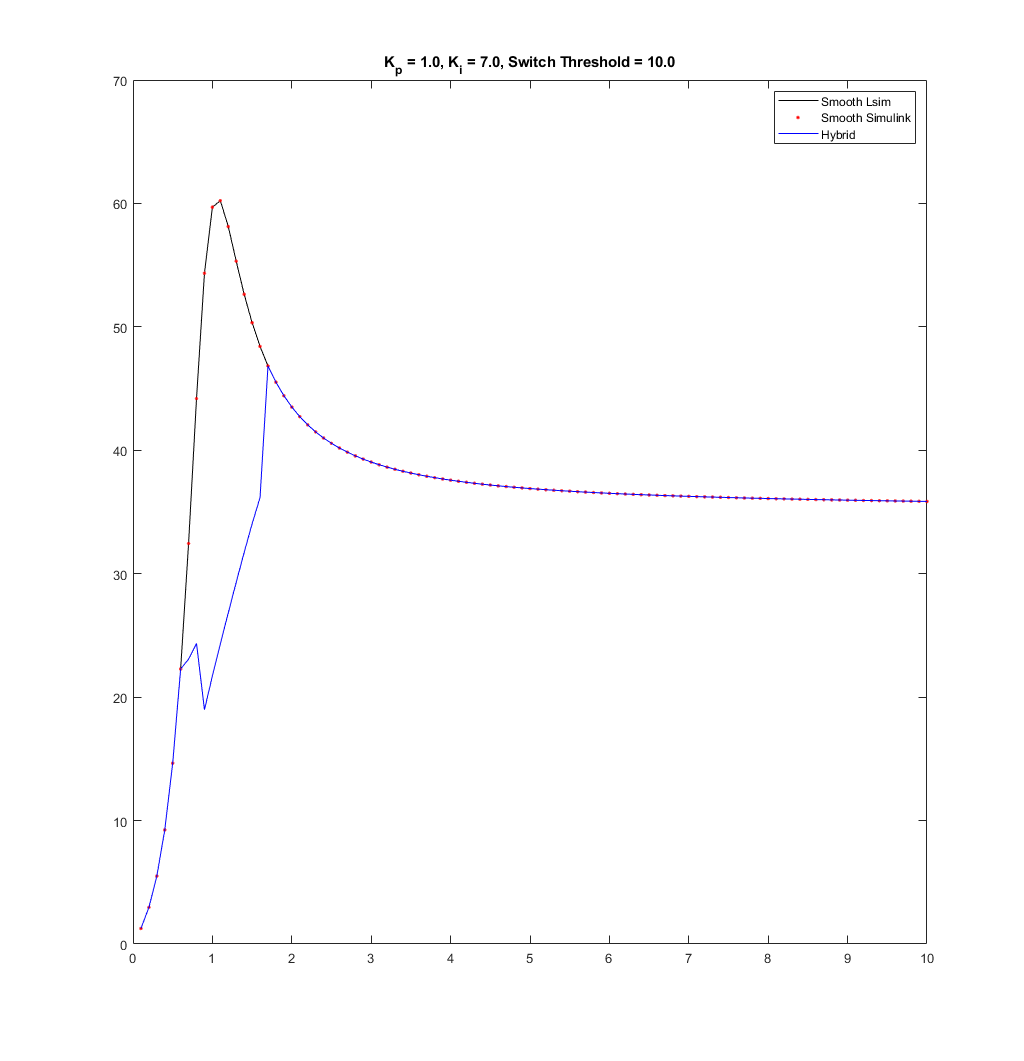

Elapsed time is 7.339322 seconds.


Elapsed time is 7.899019 seconds.


Elapsed time is 7.665973 seconds.


Elapsed time is 7.677871 seconds.


Elapsed time is 7.548670 seconds.


Elapsed time is 7.557258 seconds.


Elapsed time is 7.534349 seconds.


Elapsed time is 7.510735 seconds.


Elapsed time is 7.495151 seconds.


Elapsed time is 7.498694 seconds.


Elapsed time is 7.471884 seconds.


Elapsed time is 7.422860 seconds.


Elapsed time is 7.422411 seconds.


Elapsed time is 7.385435 seconds.


Elapsed time is 7.276694 seconds.


Elapsed time is 7.228219 seconds.


Elapsed time is 7.207879 seconds.


Elapsed time is 7.409107 seconds.


Elapsed time is 7.202242 seconds.


Elapsed time is 7.228696 seconds.


Elapsed time is 7.191800 seconds.


Elapsed time is 7.246888 seconds.


Elapsed time is 7.255566 seconds.


Elapsed time is 7.169450 seconds.


Elapsed time is 7.173432 seconds.


Elapsed time is 7.163862 seconds.


Elapsed time is 7.181194 seconds.


Elapsed time is 7.178269 seconds.


Elapsed time is 7.190454 seconds.


Elapsed time is 7.214747 seconds.


Elapsed time is 7.165798 seconds.


Elapsed time is 7.192859 seconds.


Elapsed time is 7.175413 seconds.


Elapsed time is 7.163859 seconds.


Elapsed time is 7.182088 seconds.


Elapsed time is 7.150613 seconds.


Elapsed time is 7.155491 seconds.


Elapsed time is 7.156531 seconds.


Elapsed time is 7.175762 seconds.


Elapsed time is 7.150254 seconds.


Elapsed time is 7.167340 seconds.


Elapsed time is 7.180010 seconds.


Elapsed time is 7.310216 seconds.


Elapsed time is 7.165800 seconds.


Elapsed time is 7.142844 seconds.


Elapsed time is 7.174154 seconds.


Elapsed time is 7.150219 seconds.


Elapsed time is 7.189455 seconds.


Elapsed time is 7.173426 seconds.


Elapsed time is 7.156533 seconds.


Elapsed time is 7.175154 seconds.


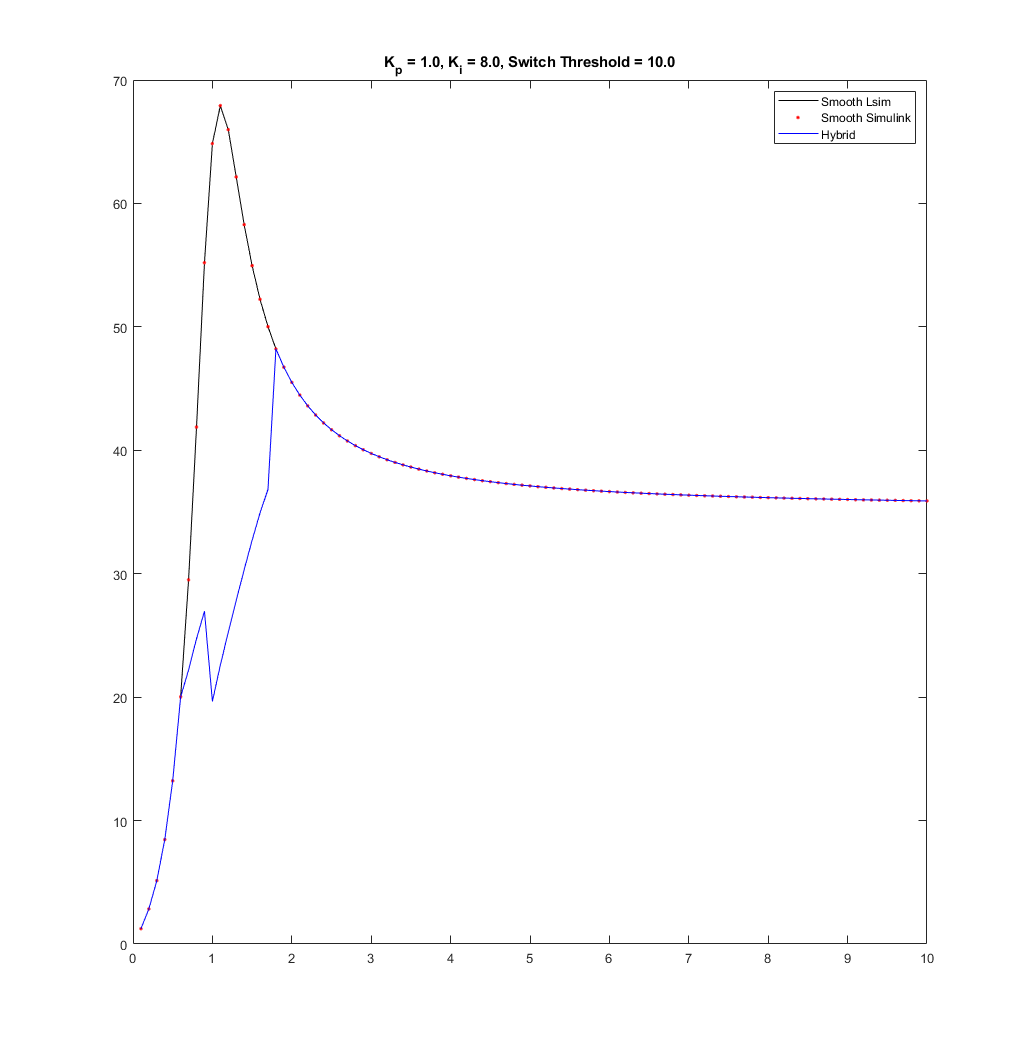

Elapsed time is 7.191683 seconds.


Elapsed time is 7.745407 seconds.


Elapsed time is 7.492725 seconds.


Elapsed time is 7.478638 seconds.


Elapsed time is 7.394571 seconds.


Elapsed time is 7.390728 seconds.


Elapsed time is 7.334975 seconds.


Elapsed time is 7.342434 seconds.


Elapsed time is 7.319151 seconds.


Elapsed time is 7.303631 seconds.


Elapsed time is 7.275627 seconds.


Elapsed time is 7.260833 seconds.


Elapsed time is 7.248867 seconds.


Elapsed time is 7.229820 seconds.


Elapsed time is 7.238302 seconds.


Elapsed time is 7.216686 seconds.


Elapsed time is 7.392984 seconds.


Elapsed time is 7.229822 seconds.


Elapsed time is 7.202000 seconds.


Elapsed time is 7.185709 seconds.


Elapsed time is 7.193188 seconds.


Elapsed time is 7.184156 seconds.


Elapsed time is 7.181040 seconds.


Elapsed time is 7.168900 seconds.


Elapsed time is 7.174337 seconds.


Elapsed time is 7.179371 seconds.


Elapsed time is 7.163104 seconds.


Elapsed time is 7.223313 seconds.


Elapsed time is 7.175275 seconds.


Elapsed time is 7.164547 seconds.


Elapsed time is 7.190842 seconds.


Elapsed time is 7.161157 seconds.


Elapsed time is 7.165026 seconds.


Elapsed time is 7.170631 seconds.


Elapsed time is 7.181447 seconds.


Elapsed time is 7.183530 seconds.


Elapsed time is 7.224136 seconds.


Elapsed time is 7.194140 seconds.


Elapsed time is 7.178025 seconds.


Elapsed time is 7.167691 seconds.


Elapsed time is 7.187431 seconds.


Elapsed time is 7.379960 seconds.


Elapsed time is 7.202390 seconds.


Elapsed time is 7.157028 seconds.


Elapsed time is 7.167815 seconds.


Elapsed time is 7.178947 seconds.


Elapsed time is 7.157258 seconds.


Elapsed time is 7.158303 seconds.


Elapsed time is 7.163861 seconds.


Elapsed time is 7.166476 seconds.


Elapsed time is 7.187070 seconds.


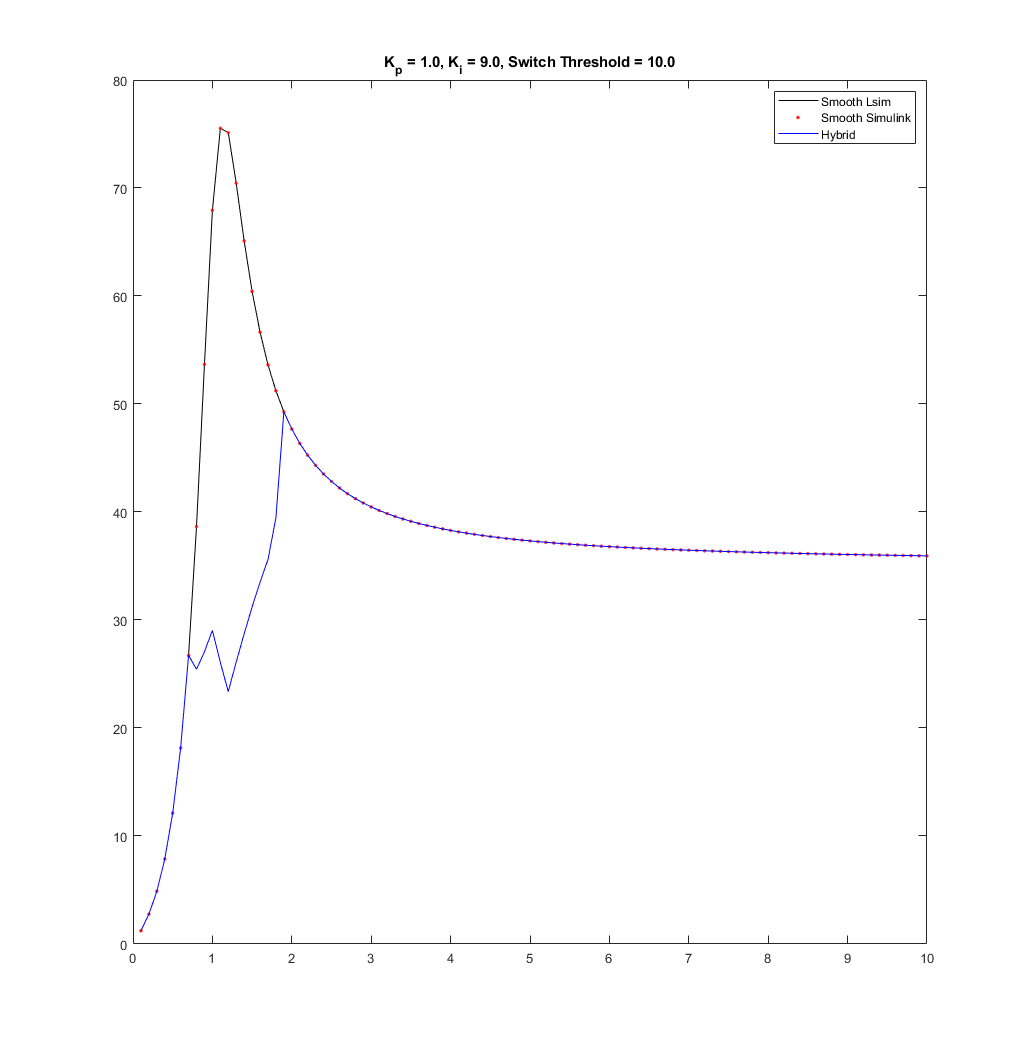

Elapsed time is 7.150310 seconds.


Elapsed time is 7.751376 seconds.


Elapsed time is 7.506365 seconds.


Elapsed time is 7.440989 seconds.


Elapsed time is 7.409179 seconds.


Elapsed time is 7.406399 seconds.


Elapsed time is 7.356525 seconds.


Elapsed time is 7.351750 seconds.


Elapsed time is 7.329683 seconds.


Elapsed time is 7.306544 seconds.


Elapsed time is 7.293883 seconds.


Elapsed time is 7.277363 seconds.


Elapsed time is 7.244443 seconds.


Elapsed time is 7.247035 seconds.


Elapsed time is 7.232266 seconds.


Elapsed time is 7.386549 seconds.


Elapsed time is 7.220581 seconds.


Elapsed time is 7.195561 seconds.


Elapsed time is 7.209647 seconds.


Elapsed time is 7.222453 seconds.


Elapsed time is 7.195186 seconds.


Elapsed time is 7.214880 seconds.


Elapsed time is 7.184773 seconds.


Elapsed time is 7.208843 seconds.


Elapsed time is 7.203671 seconds.


Elapsed time is 7.187721 seconds.


Elapsed time is 7.185199 seconds.


Elapsed time is 7.203213 seconds.


Elapsed time is 7.189017 seconds.


Elapsed time is 7.231686 seconds.


Elapsed time is 7.176945 seconds.


Elapsed time is 7.170110 seconds.


Elapsed time is 7.169789 seconds.


Elapsed time is 7.190309 seconds.


Elapsed time is 7.183597 seconds.


Elapsed time is 7.200370 seconds.


Elapsed time is 7.182857 seconds.


Elapsed time is 7.183420 seconds.


Elapsed time is 7.174462 seconds.


Elapsed time is 7.177671 seconds.


Elapsed time is 7.357978 seconds.


Elapsed time is 7.240364 seconds.


Elapsed time is 7.181752 seconds.


Elapsed time is 7.193864 seconds.


Elapsed time is 7.185927 seconds.


Elapsed time is 7.174419 seconds.


Elapsed time is 7.171260 seconds.


Elapsed time is 7.209200 seconds.


Elapsed time is 7.184723 seconds.


Elapsed time is 7.152923 seconds.


Elapsed time is 7.181727 seconds.


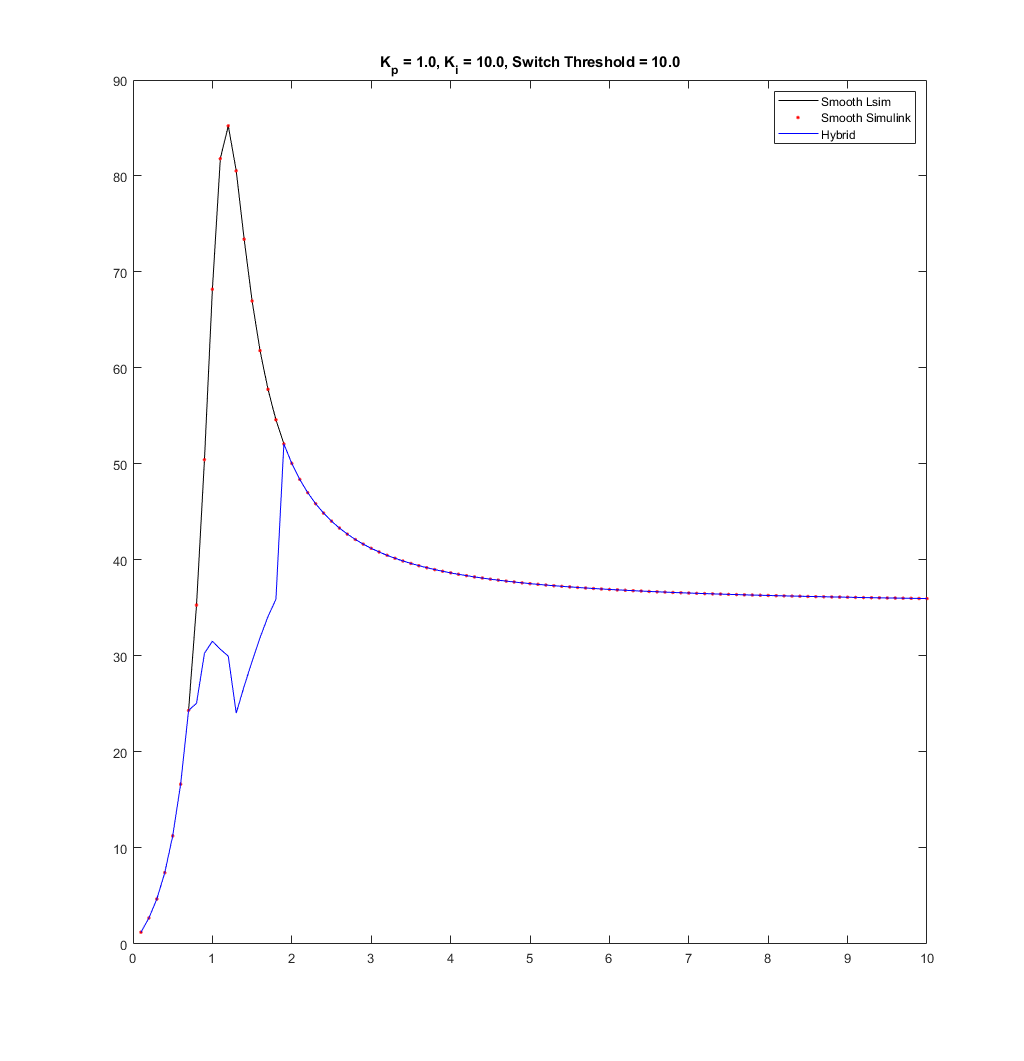

Elapsed time is 7.184714 seconds.


if togRMSFreq == 1  
    %First, the smooth system using lsim
    Kp = 3:1:10;
    for j = 1:length(Kp)
        Ki = KiStatic;
        td =tdStatic;
        smoothRMSE = simRMSE(Kp(j),Ki,td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        hybridInfRMSE = simRMSE(Kp(j),Ki,td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            hybridTempRMSE = simRMSE(Kp(j),Ki,td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp(j),Ki,switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp(j)),'_Ki_',num2str(Ki),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
    
        Ki = 1:1:10;
    for j = 1:length(Ki)
        Kp = KpStatic;
        td =tdStatic;
        smoothRMSE = simRMSE(Kp,Ki(j),td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        hybridInfRMSE = simRMSE(Kp,Ki(j),td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            hybridTempRMSE = simRMSE(Kp,Ki(j),td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp,Ki(j),switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp),'_Ki_',num2str(Ki(j)),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
   
    
    
    

%     figure
%     plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r')
%     lgd{1} = 'Smooth Lsim';
%     lgd{2} = 'Smooth Simulink';
%     hold on
%     switchThreshRange = [2.5 2.8 3 3.3 3.8 4 4.5];
%     for i = 1:length(switchThreshRange)
%         hybridTempRMSE = simRMSE(Kp,Ki,td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
%         plot(sinfreqs,hybridTempRMSE)
%         lgd{2+i} = strcat('Hybrid - Switch Threshold = ',num2str(switchThreshRange(i)));
%     end
%     
%     xlabel('Input Sin Frequency (Hz)')
%     ylabel('RMSE (deg/s)')
%     legend(lgd,'Location','northwestoutside')
%     hold off   
end

# Sweep across switching threshold

%Input
V_in = [t' sos'];

%Parameters
sac_time = 0.04; %Saccade completion "delay"
n_delay = .04; %Neurological Delay
T_lim_up = inf; %Biological Torque Limit upper
T_lim_low = -inf; %Biological Torque Limit upper
K_P = 6; %Proportional Gain
K_I = .05; %Integral Gain of smooth system


switch_threshbig = 0.01:0.01:5; %Integrated error threshold for switching between smooth/saccadic
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    soserrorsingle(i) = sum(abs(sos'-out.V_out));
end

figure
plot(switch_threshbig,normalize(soserrorsingle,'range'))
hold on

%Input
V_in = [t' chirps'];
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    chirpserrorsingle(i) = sum(abs(chirps'-out.V_out));
end

plot(switch_threshbig,normalize(chirpserrorsingle,'range'))

K_P = 3; %Proportional Gain

V_in = [t' sos'];
switch_threshbig = 0.01:0.01:5; %Integrated error threshold for switching between smooth/saccadic
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    soserrorsingle(i) = sum(abs(sos'-out.V_out));
end

plot(switch_threshbig,normalize(soserrorsingle,'range'))

%Input
V_in = [t' chirps'];
for i = 1:size(switch_threshbig,2)
    switch_thresh = switch_threshbig(i);
    out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');
    chirpserrorsingle(i) = sum(abs(chirps'-out.V_out));
end

plot(switch_threshbig,normalize(chirpserrorsingle,'range'))
ylabel('Normalized Error')
xlabel('Switching Threshold')
legend('SoS Error, K_p = 6','Chirp Error, K_p = 6','SoS Error, K_p = 3','Chirp Error, K_p = 3')

# Optimal Point Gain Sweep

Prange = 1:1:15;
Irange = 1:1:15;
switchrange = 0.5:0.5:10;
freqrange = 1:1:5;
estimatedTimeHrs = (.035*numel(Prange)*numel(Irange)*numel(switchrange)*numel(freqrange))/3600
estimatedTimeMins = (.035*numel(Prange)*numel(Irange)*numel(switchrange)*numel(freqrange))/60
estimatedTimeSecs = (.035*numel(Prange)*numel(Irange)*numel(switchrange)*numel(freqrange))/1

%Parameters
sac_time = 0.04; %Saccade completion "delay"
n_delay = .04; %Neurological Delay
T_lim_up = inf; %Biological Torque Limit upper
T_lim_low = -inf; %Biological Torque Limit upper

%Input
%V_in = [t' sos'];

% %Parallel Simulation Setup
% tic
% numSims = size(switchrange,2)*size(Prange,2)*size(Irange,2);
% clear simIn
% simIn(1:numSims) = Simulink.SimulationInput(simName);
% 
% iter = 1;
% for i = 1:size(Prange,2)
%     for j = 1:size(Irange,2)
%         for k = 1:size(switchrange,2) 
%             %Constants
%             simIn(iter) = simIn(iter).setVariable('sac_time',sac_time,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('n_delay',n_delay,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('T_lim_up',T_lim_up,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('T_lim_low',T_lim_low,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('G_plant',G_plant,'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('V_in',V_in,'Workspace',simName);
%             
%             %Variables
%             simIn(iter) = simIn(iter).setVariable('switch_thresh',switchrange(k),'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('K_P',Prange(i),'Workspace',simName);
%             simIn(iter) = simIn(iter).setVariable('K_I',Irange(j),'Workspace',simName);
%             
%             iter = iter + 1;
%         end
%         
%     end
% end
% out = parsim(simIn,'UseFastRestart','on');
% toc

tic
minswitch = zeros(size(freqrange,2),size(Prange,2)*size(Irange,2),3);
error = zeros(1,size(switchrange,2));
iter=1;
for l = 1:size(freqrange,2)
   puresine = 50*sin(2*pi*freqrange(l)*t);
   V_in = [t' puresine'];
   for i = 1:size(Prange,2)
    for j = 1:size(Irange,2)
        K_P = Prange(i);
        K_I = Irange(j);

        for k = 1:size(switchrange,2)
            switch_thresh = switchrange(k);
            out = sim('HybridSaccadeFF.slx');
            error(k) = sum(abs(sos'-out.V_out));
        end
        
        [minerror,index] = min(error);
        minswitch(l,iter,:) = [K_P K_I switchrange(index)];
        iter=iter+1;
    end  
    end 
end

toc

filename1 = strcat('ch','_',num2str(scale),'_',num2str(f_start),'_',num2str(f_end),'_');
filename2 = strcat('ssf','_',num2str(f(1)),'_',num2str(f(2)),'_',num2str(f(3)),'_');
filename3 = strcat('ssp','_',num2str(p(1)),'_',num2str(p(2)),'_',num2str(p(3)),'_');
filename4 = strcat('kp','_',num2str(Prange(1)),'_',num2str(Prange(2)-Prange(1)),'_',num2str(Prange(end)),'_');
filename5 = strcat('ki','_',num2str(Irange(1)),'_',num2str(Irange(2)-Irange(1)),'_',num2str(Irange(end)),'_');
filename6 = strcat('sw','_',num2str(switchrange(1)),'_',num2str(switchrange(2)-switchrange(1)),'_',num2str(switchrange(end)));
filename7 = strcat('sw','_',num2str(freqrange(1)),'_',num2str(freqrange(2)-freqrange(1)),'_',num2str(freqrange(end)));
filename = strcat(filename1,filename2,filename3,filename4,filename5,filename6,'.mat')
save(filename,'minswitch','chirps','sos','scale')


for i = 1:size(freqrange,2)
    figure('Renderer', 'painters', 'Position', [10 10 1000 700])
    set(gcf, 'Color', 'w');
    sf = fit([minswitch(i,:,1)', minswitch(i,:,2)'],minswitch(i,:,3)','cubicinterp');
    plot(sf)
end




ax = gca;
ax.XAxis.FontSize = 12;
ax.XAxis.FontName = 'Segoe UI';
ax.YAxis.FontSize = 12;
ax.YAxis.FontName = 'Segoe UI';
ax.ZAxis.FontSize = 12;
ax.ZAxis.FontName = 'Segoe UI';
xlabel('K_P','FontName','Segoe UI Semibold','FontSize',14)
ylabel('K_I','FontName','Segoe UI Semibold','FontSize',14)
zlabel('Optimum Switching Threshold','FontName','Segoe UI Semibold','FontSize',14)
box on
view(-30,25)
